# MR Imaging

This tutorial covers two related topics.  

First, pulse sequence methods for measuring T1 and T2 are illustrated.  Two types of pulse sequences (inversion recovery and spin echo) are introduced.  These two sequences selectively emphasize the T1 or T2 tissue properties.

Then, the tutorial continues with a very simple example of how one can form images of the relaxation constants (T1 or T2) at different positions.

- **Class**:     Psych 204A

- **Tutorial**:  MR Imaging

- **Author**:    Wandell

- **Date**:      03.15.04

- **Duration**:  90 minutes

Checked: 

-    Rory Sayres: Oct, 2007 

-    Jon Winawer: Sep, 2009

-    Brian Wandell:  January, 2018

## T1 signals (Inversion-Recovery)

Inversion-Recovery pulse sequences are a method for measuring T1 relaxation (spin-lattice). These types of measurements are commonly used to measure brain anatomy.  The method is effective at contrasting the response between gray and white matter.

As the sequence name suggests, the pulse sequence first inverts the net magnetization (180 deg pulse). Then, the sequences simply pauses for a time, TI, to let the longitudinal magnetization recover towards steady state across the tissue. Then, a 90deg pulse is delivered that places the net magnetization in the transverse plane. The transverse magnetization is measured right away, before significant dephasing, in order to estimate the T1 properties.

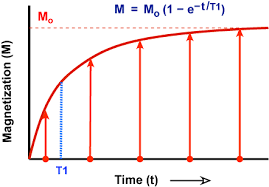

To visualize the events, we suggest you run this code a few times.  The first plot shows the 180-TI-90 sequence for a relatively slow T1 value.

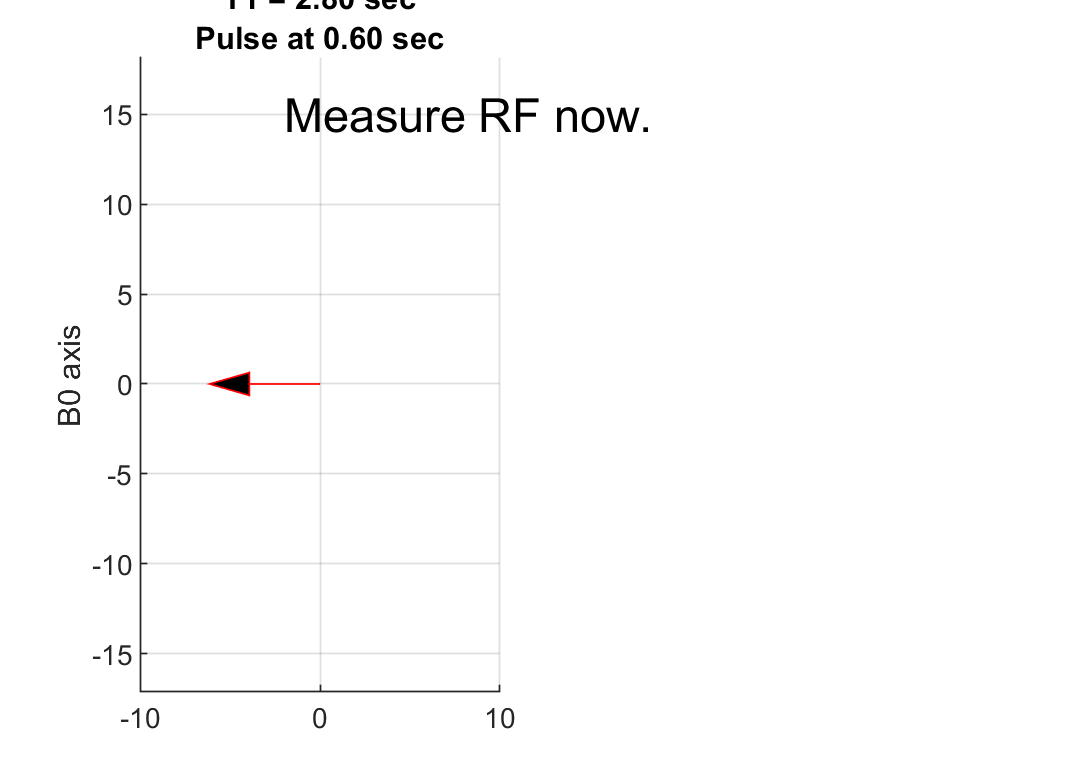

mrvNewGraphWin;
subplot(1,2,1);
T1 = 2.8;       % 2.8 sec T1
Pulse = 0.6;    % Time of 90 deg pulse
title(sprintf('T1 = %.2f sec\nPulse at %.2f sec',T1,Pulse));
inversionRecovery(T1,Pulse);

### A faster T1 relaxation

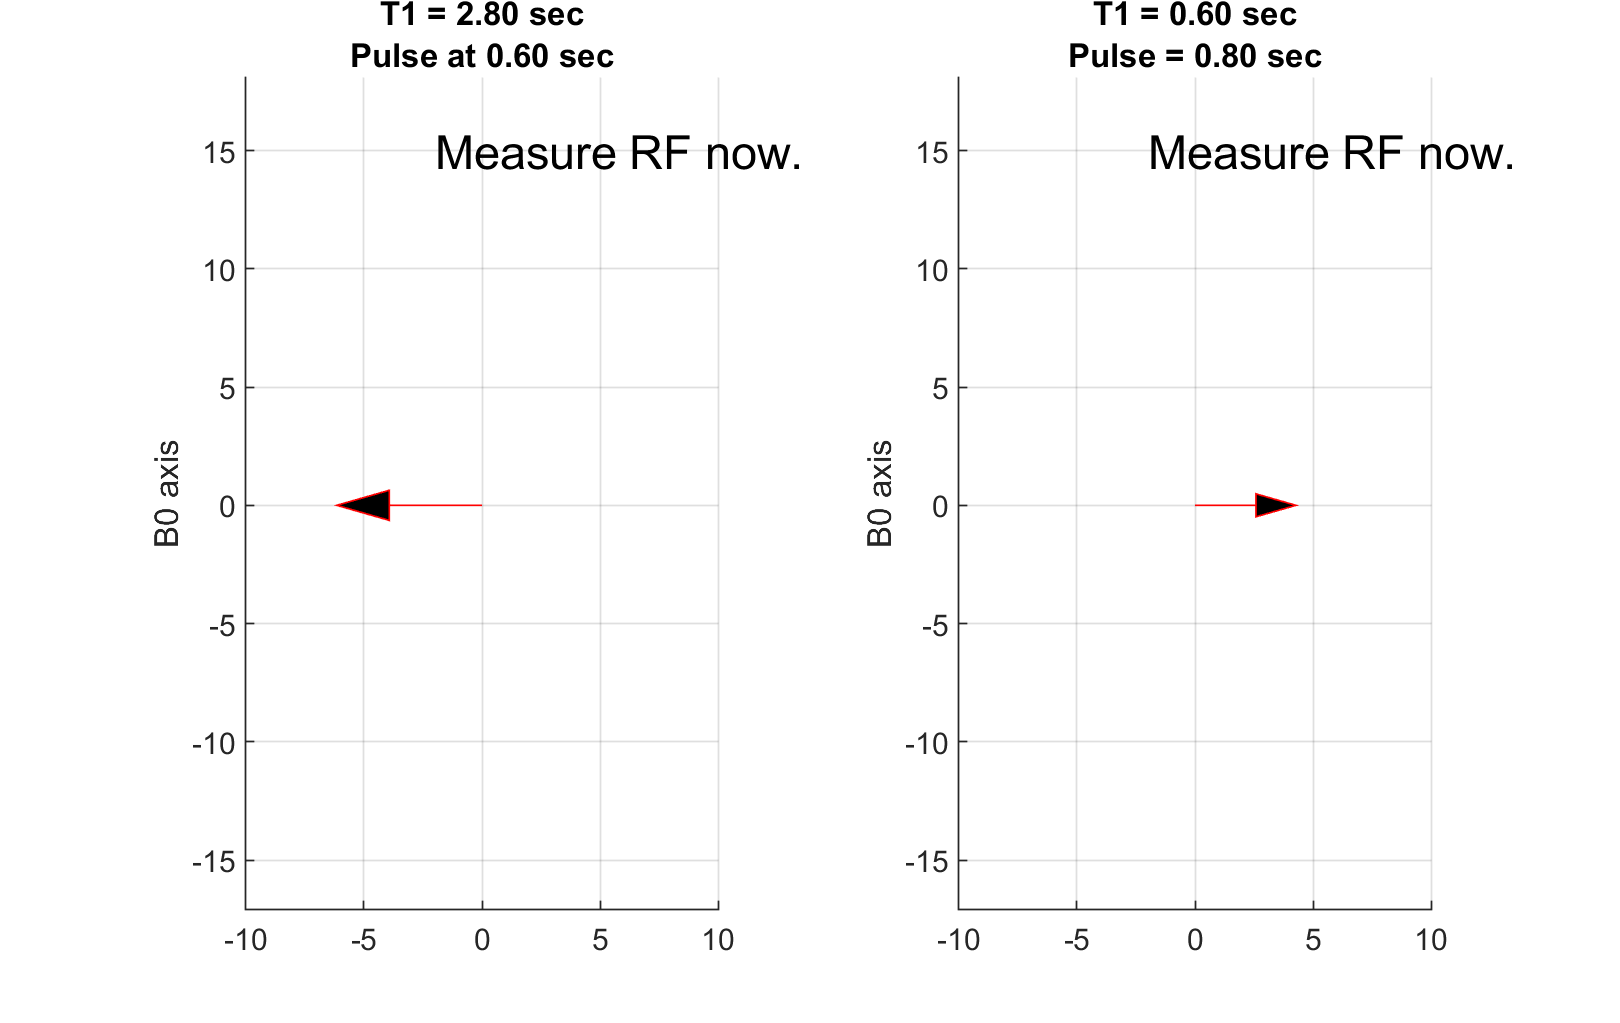

subplot(1,2,2); cla
T1 = 0.6;        % 0.6 sec T1
Pulse = 0.8;    % Time of 90 deg pulse
title(sprintf('T1 = %.2f sec\nPulse = %.2f sec',T1,Pulse));
inversionRecovery(T1,Pulse);

## Question 1

If we apply a 90-degree RF pulse at the time when exactly half the signal has recovered, what do you expect the transverse magnetization to be?

Comparing the two panels, you can see that the amplitude of the  transverse magnetization depends on the value of T1. The  90 deg pulse lets us measure the size of the longitudinal magnetization.  The measurement takes place immediately after this 90 deg flip, so there is not much time for spin-spin dephasing.  Thus, the signal we measure is mainly the size of T1.  That is why inversion recovery sequences are called 'T1-weighted'.

## T2 **Spin Echo (Hahn)**

To make a T2 measurement we need only to flip the net magnetization 90 deg and then measure the signal decay as the spins dephase. The difficulty, however, is that the T2 reduction is very fast. The spin-spin dephasing occurs so quickly that it is almost impossible to obtain a T2 measurement soon enough after the 90 deg flip. 

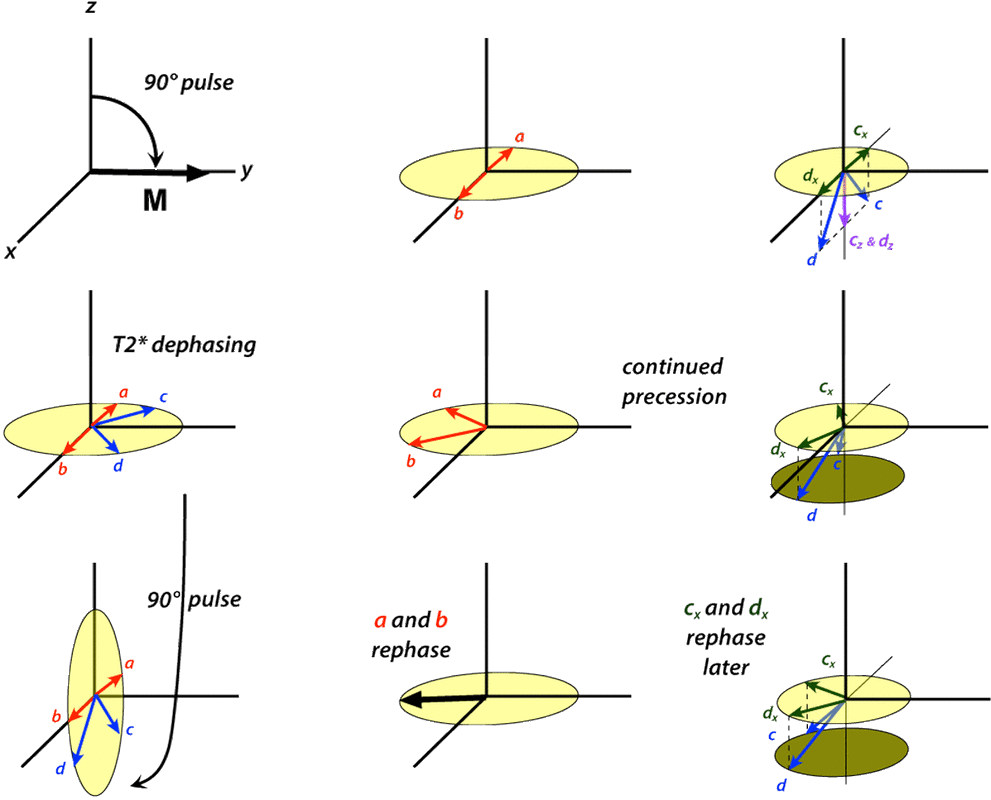

The **Hahn Spin Echo**, and another method called the **Gradient Echo**, make it possible to separate the time between the RF pulse and the measurement.  Many MR pulse sequences measure these echos.

The next visualization shows two spins within a single voxel. These spins are experiencing slightly differeent local magnetic fields. Consequently, one precesses around the origin slightly faster than the other. After a little time the signals are well out of phase. Then, a 180 deg inverting pulse is introduced. This pulse rotates the spins around the horizontal axis (x-axis). Seen within the plane, this causes the two spins to reverse positions so that the leader becomes the follower. The leader is still in a higher local field, and so after a while it catches up. At that moment the spin phases come together to create an echo of the signal after the first 90 deg pulse. This echo happens at a point in time that is well separated from the inverting pulse, making it easier to measure.

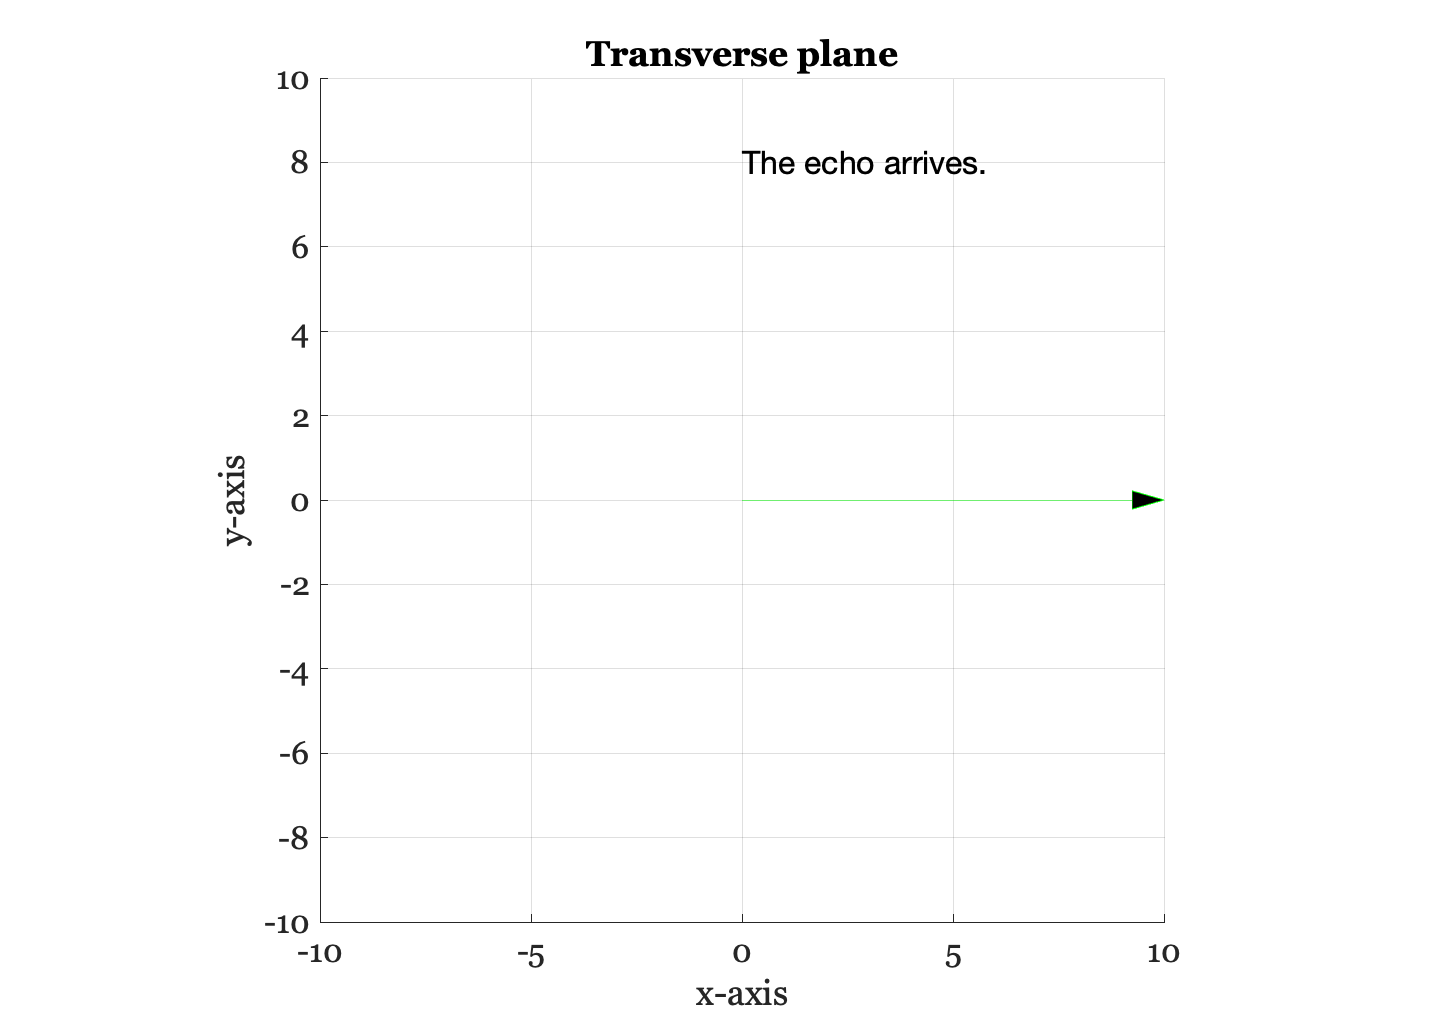

% The time until the inverse pulse determines when the echo will occur
TE = 16;      % ms   
clf; 
spinEcho(TE);

## MR Image formation

How can we distinguish signals from different locations?  This is the key step in learning how to form an image of the MR time constant's properties.

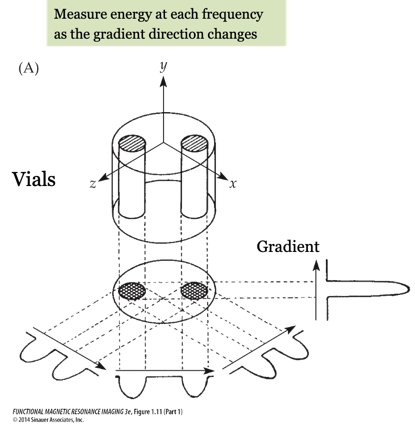

Consider a simple situation in which we have two beakers sitting next to one another on a table.  **Both contain water.  **Suppose the magnetic field is uniform, and suppose that we measure T1.

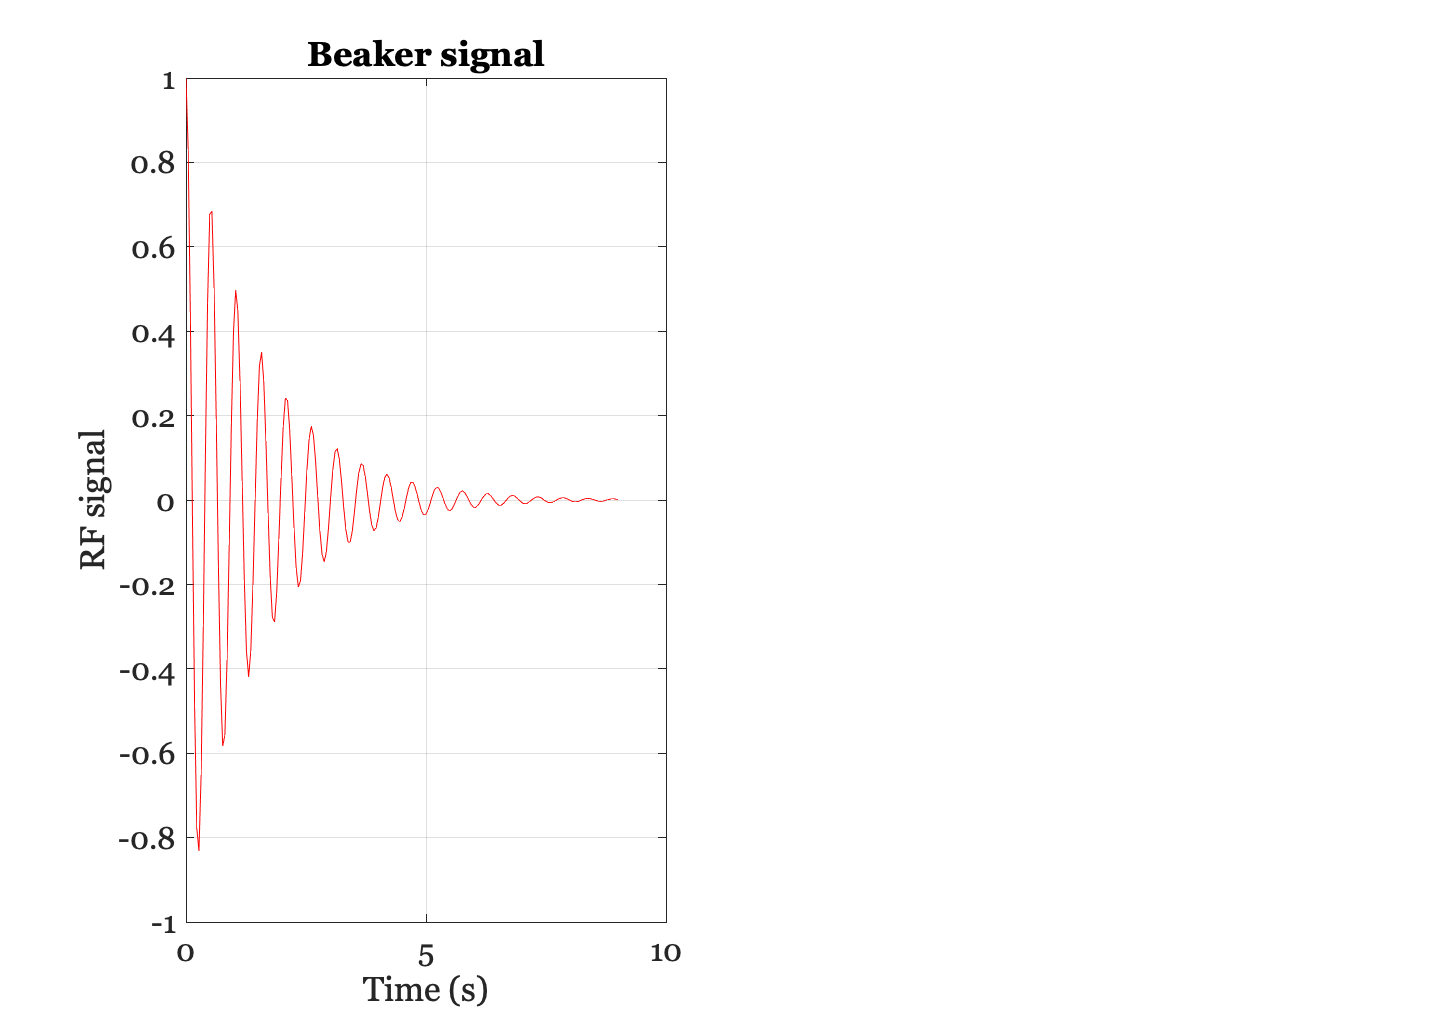

% We are going to need these variables to develop the story.  So, run these
% few lines before continuing.
Mo = 1;                 % Net magnetization
larmorFreq(1) = 12;     % Larmor frequency in MHz/10
larmorFreq(2) = 18;     % Larmor frequency in MHz/10
T1(1) = 1.5;
T1(2) = 3;
t = (0:.005:1)*(3*max(T1)); % Time samples in secs

% The function rfSignal produces the RF signal that we will measure given a
% particular time constant and Larmor frequency.
signal = rfSignal(T1(1),Mo,t,larmorFreq(1));
figure(1); clf
subplot(1,2,1), plot(t,signal); grid on
xlabel('Time (s)'); ylabel('RF signal'); title('Beaker signal');

### The RF signal is periodic.  

We can summarize the amplitude and frequency of this signal by plotting the Fourier Transform amplitude spectrum.  This plot measures the amplitude of each harmonic (temporal frequency) in the signal.

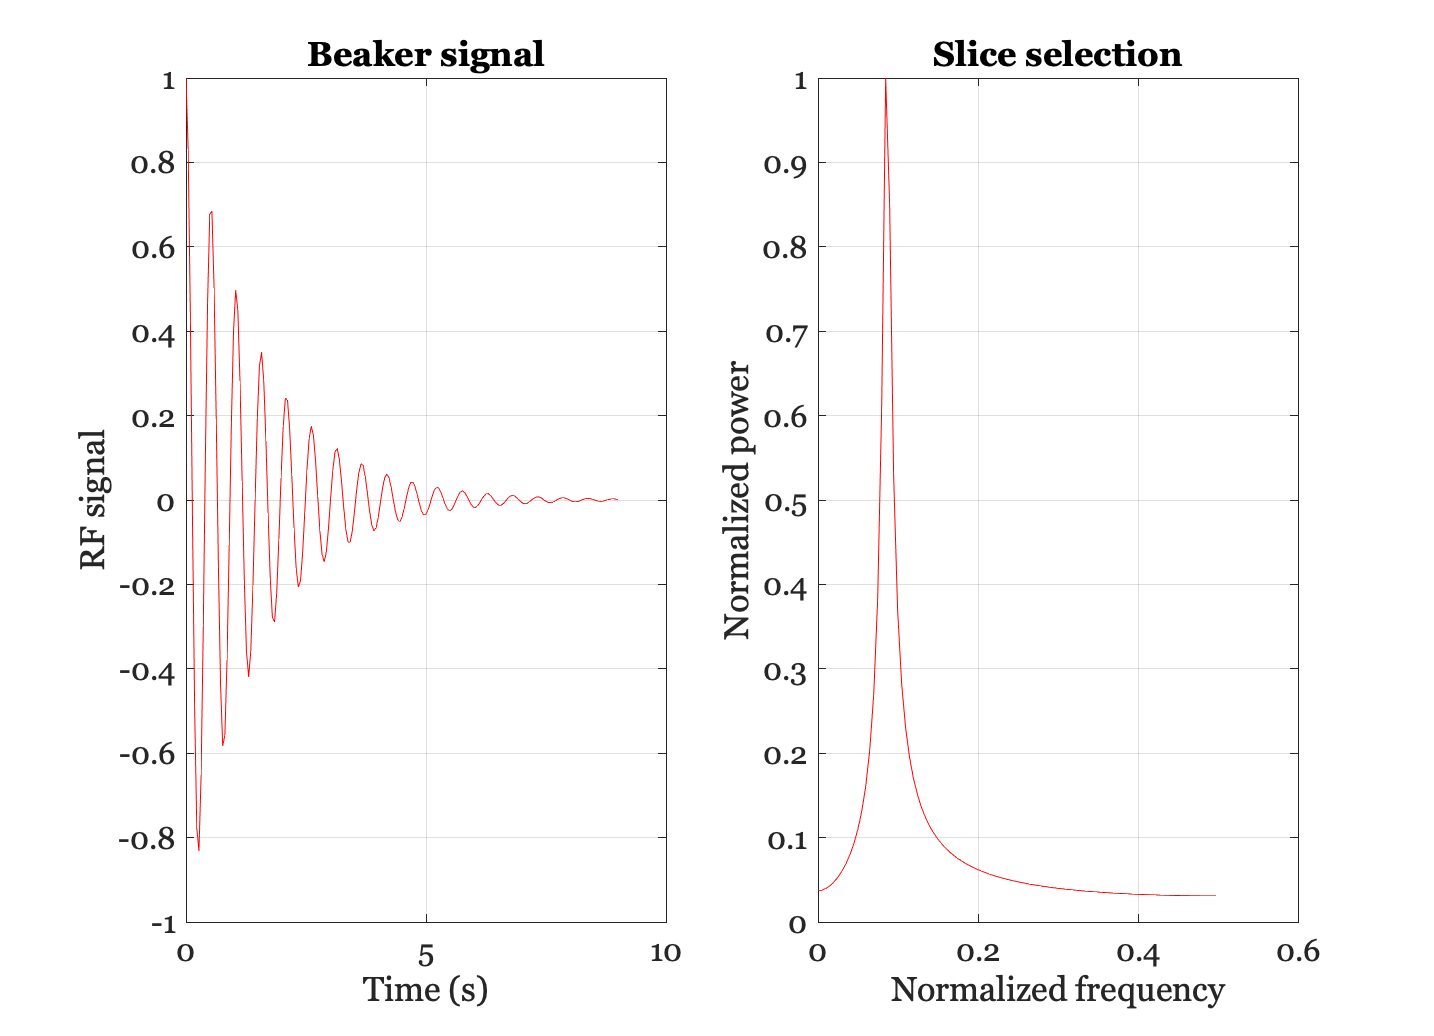

subplot(1,2,2), cla
[s,f] = powerSpecDens(signal);
plot(f,s); grid on;
xlabel('Normalized frequency'); ylabel('Normalized power'); title('Slice selection')

### Consider the signal as the relaxation constant  increases.  

Notice that over the same period of time, the rfSignal has a larger amplitude (there is less decay).

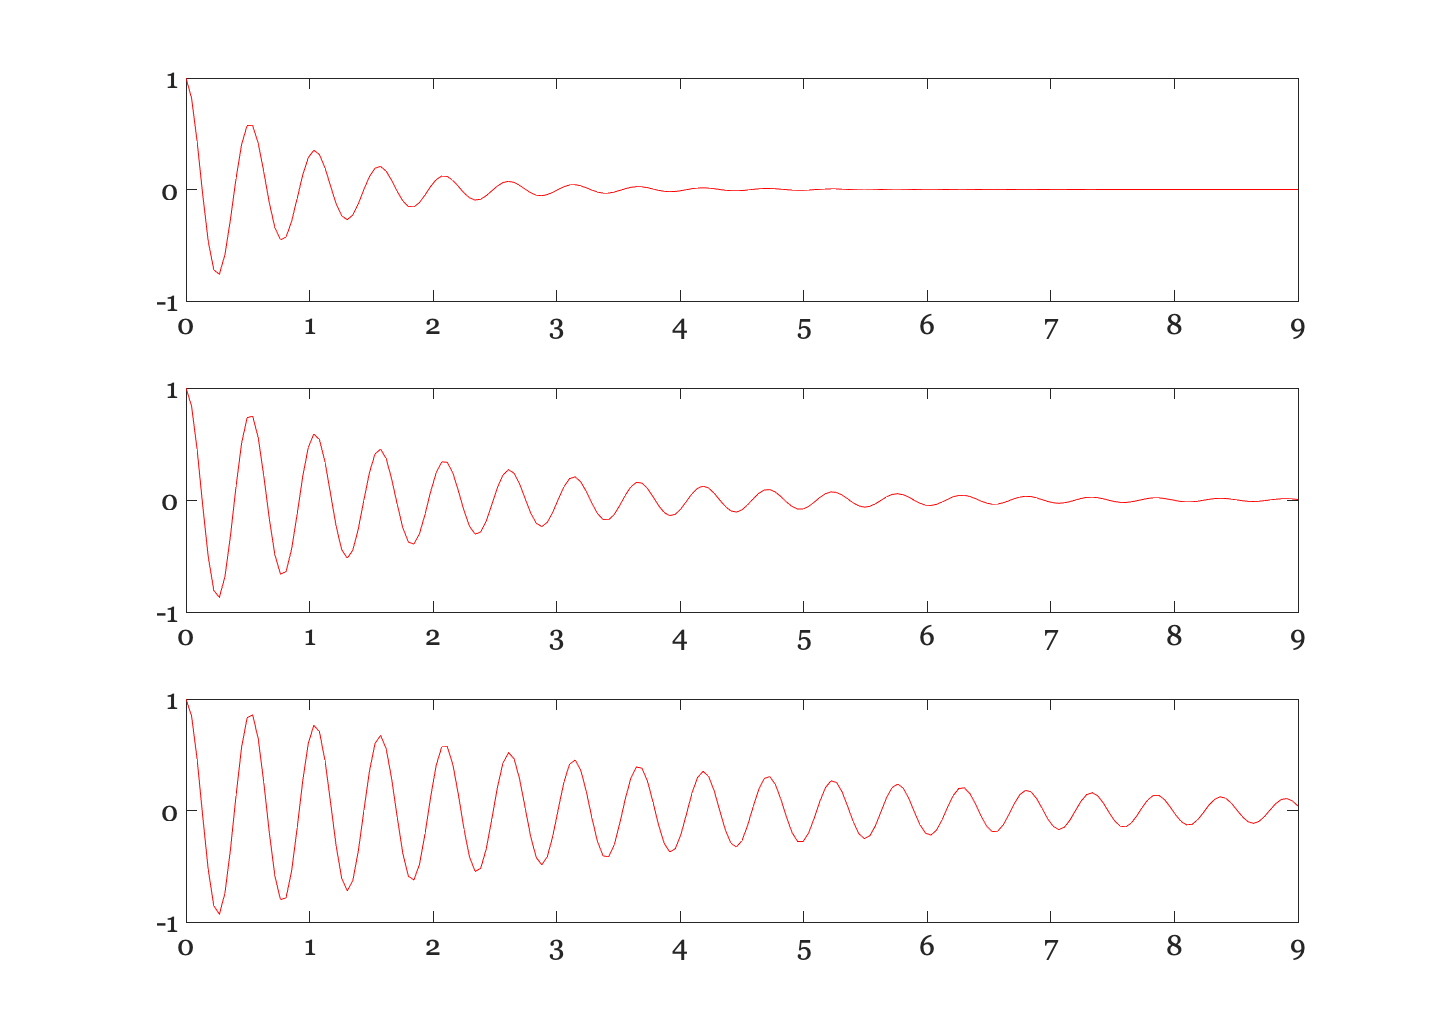

clf;
tConstant = [1,2,4]; 
for ii=1:3
    subplot(3,1,ii); set(gca,'ylim',[-1,1]);
    signal = rfSignal(tConstant(ii),Mo,t,larmorFreq(1));
    plot(t,signal); hold on;
end
hold off

## Question 2

If you were to plot the Fourier Transform for each of the three subplots, how do you expect they would differ?

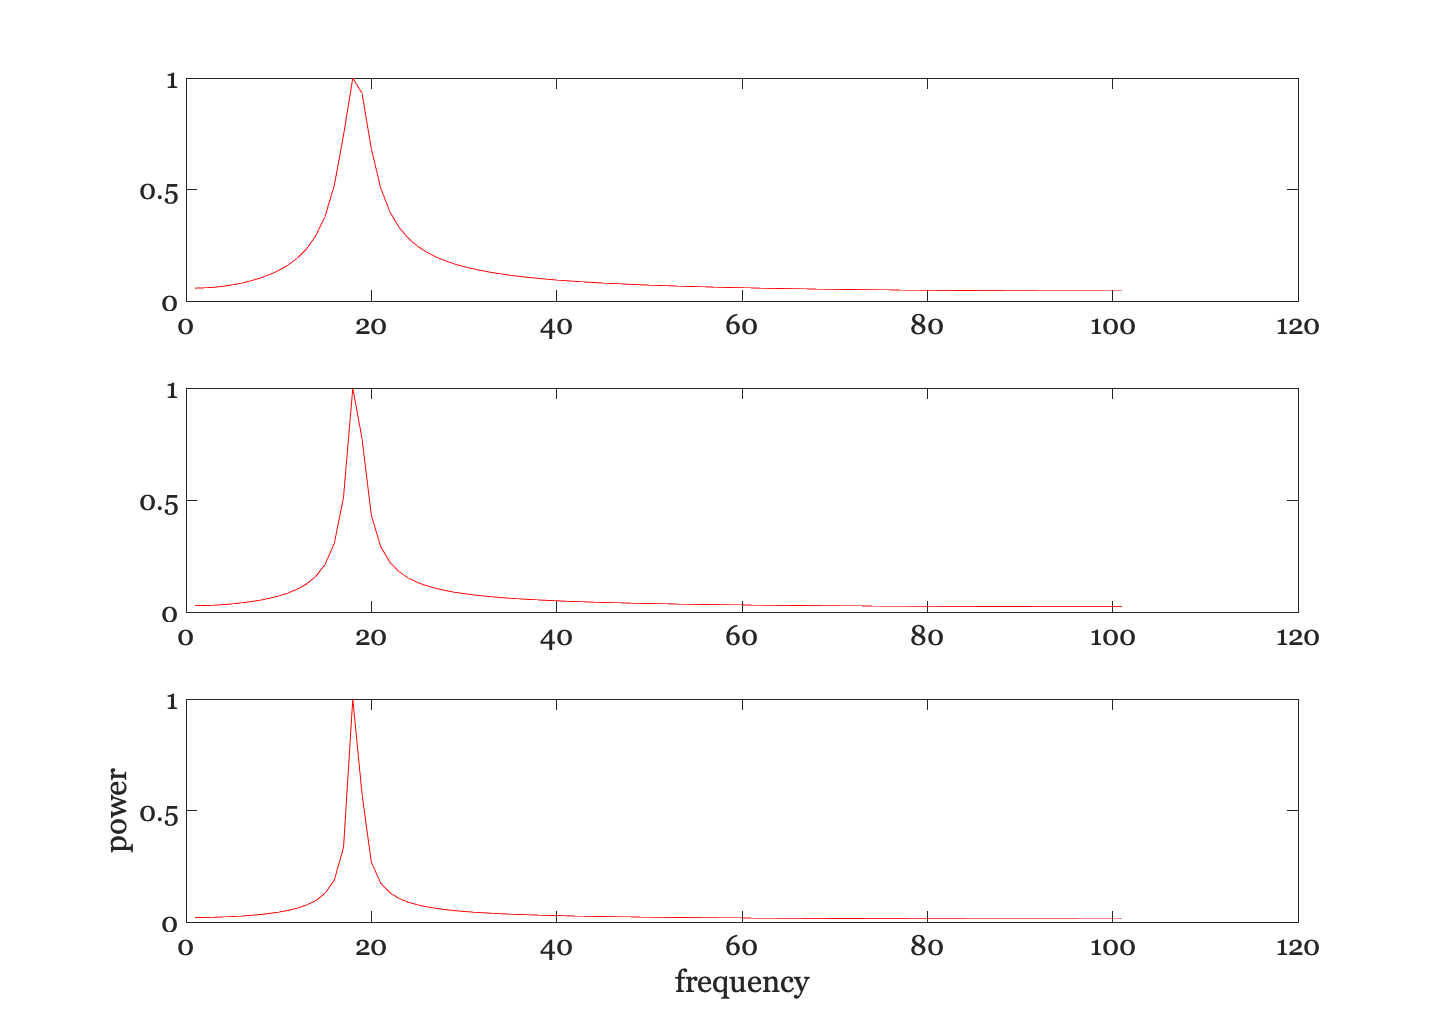

clf; 
for ii=1:3
    subplot(3,1,ii); set(gca,'ylim',[-1,1]);
    signal = rfSignal(tConstant(ii),Mo,t,larmorFreq(1));
    plot(powerSpecDens(signal));
end
xlabel('frequency'); ylabel('power')
hold off

## Changing the field strength

Now, suppose that we change the magnetic field strength. Remember that the Larmor frequency is proportional to the magnetic field. Consequently, the frequency of the RF signal will increase. We can compare the signals at two different frequencies as follows:

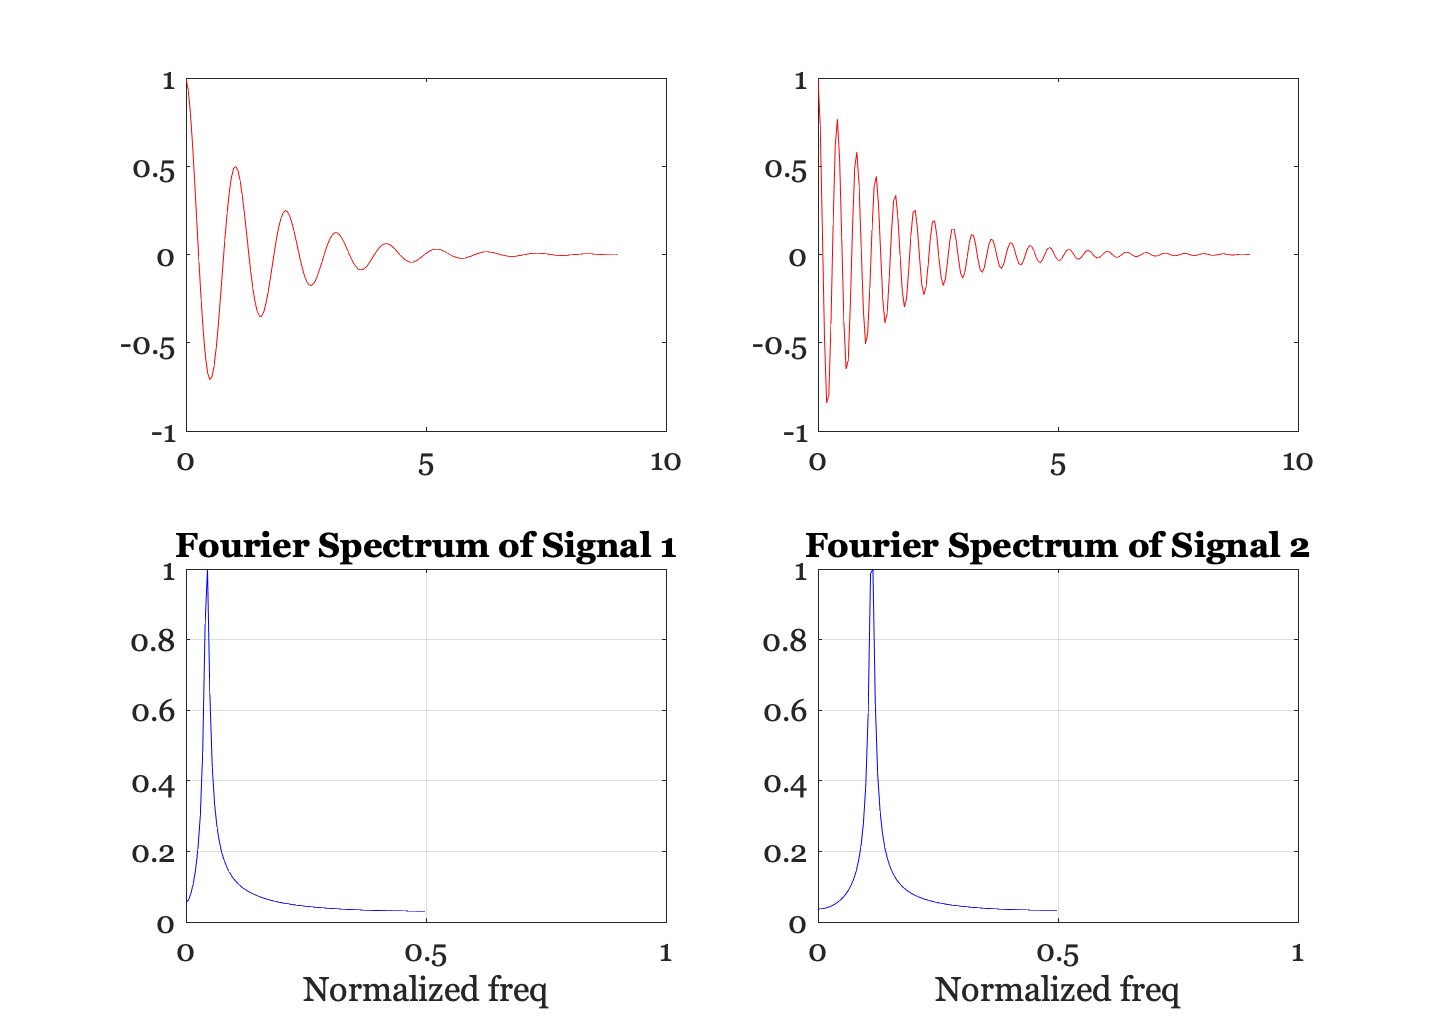

larmorFreq = [6, 124];
nFreqs = length(larmorFreq);

clf
for ii=1:nFreqs
    subplot(2,nFreqs,ii); set(gca,'ylim',[-1,1]);
    signal = rfSignal(T1(1),Mo,t,larmorFreq(ii));
    plot(t,signal)
end

% It is easiest to see the change in frequency if we compute the Fourier
% Transform of the two signals.
for ii=1:nFreqs
    subplot(2,nFreqs,ii+nFreqs); set(gca,'ylim',[0,25]);
    signal = rfSignal(T1(1),Mo,t,larmorFreq(ii));
    [s,f] = powerSpecDens(signal);
    plot(f,s,'b-'); grid on; 
    set(gca,'ylim',[0,1],'xlim',[0 1]); grid on;
    title(sprintf('Fourier Spectrum of Signal %.0f',ii))
    xlabel('Normalized freq')
end

This figure is important.  It shows that the frequency of the response from each beaker depends on the local magnetic field.  We have already seen that the amplitude at the response frequency depends on the time constant.  We can take advantage of these two observations by introducing a gradient into the magnetic field. 

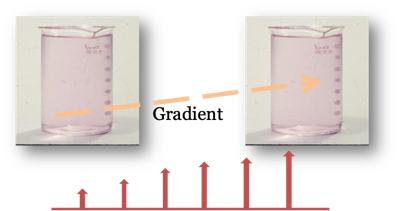

By inserting a gradient, the two beakers experience slightly different magnetic fields and thus the signals have two different Larmor frequencies. The combined RF signal from the two beakers will be the sum of the signals from the two beakers.

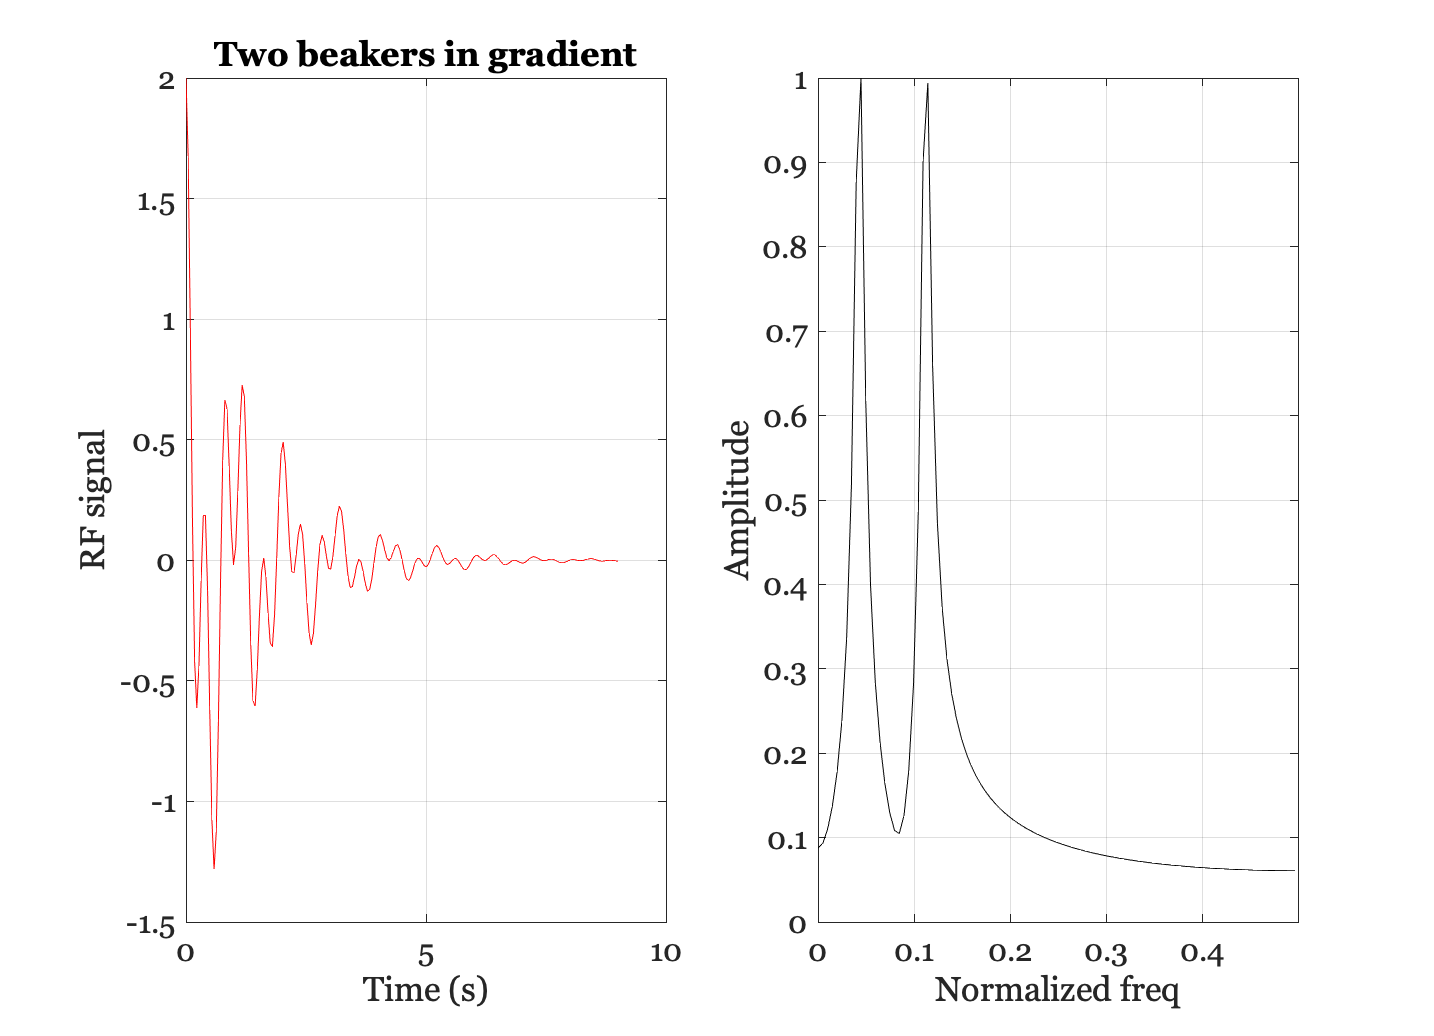

signal =  rfSignal(T1(1),Mo,t,larmorFreq(1)) + rfSignal(T1(1),Mo,t,larmorFreq(2));
clf, subplot(1,2,1), plot(t,signal); grid on
xlabel('Time (s)'); ylabel('RF signal'); title('Two beakers in gradient');

% We can see the amplitude of the signals from each of the beakers by
% plotting the Fourier Transform spectrum
subplot(1,2,2); cla
[s,f] = powerSpecDens(signal);
plot(f,s,'k'); grid on;
set(gca,'ylim',[0,1],'xlim',[0 0.5]); grid on;
xlabel('Normalized freq')
ylabel('Amplitude')

Finally, if the two beakers represent substances with different time constants, we will be able to measure this by estimating the amplitudes of the two peaks in the spectrum.  Here, we create a signal in which the two beakers are in a gradient and the substances have slightly different time constants.

signal =  rfSignal(T1(1),Mo,t,larmorFreq(1)) + rfSignal(T1(2),Mo,t,larmorFreq(2));
clf, subplot(1,2,1), plot(t,signal,'k'); grid on
xlabel('Time (s)'); ylabel('RF signal'); title('Two beakers in gradient');

You can see that the amplitude of peaks in the signal change, reflecting the different time constants.  We can distinguish which amplitude is associated with which beaker because their responses are at different frequencies.

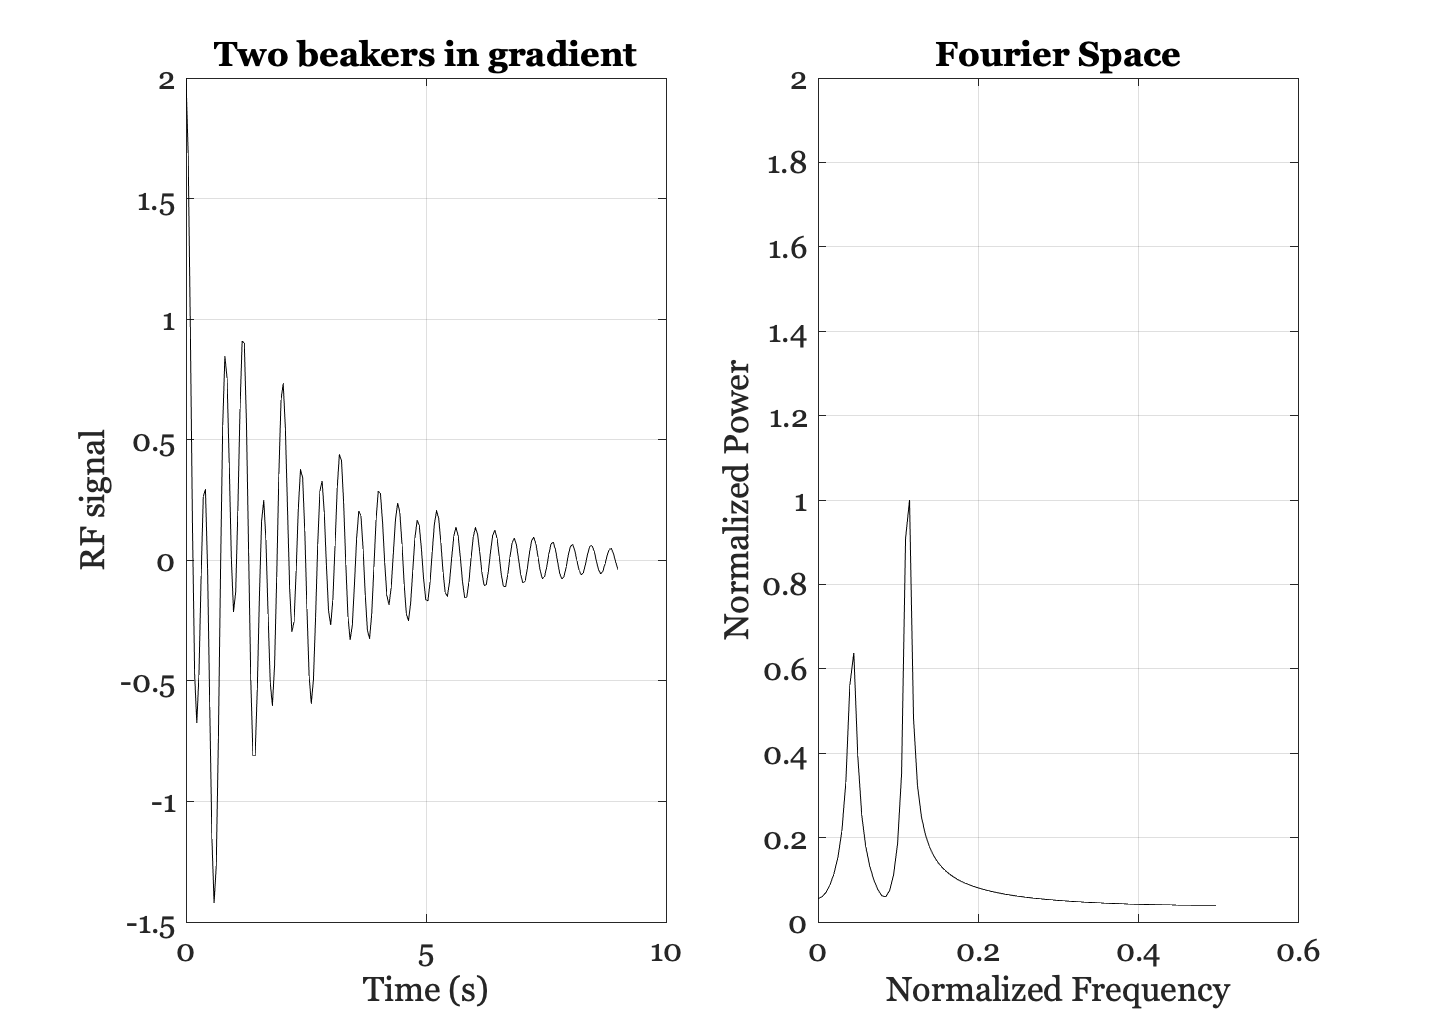

subplot(1,2,2); cla
[s,f] = powerSpecDens(signal);
plot(f,s,'k'); grid on;

set(gca,'ylim',[0,2]); grid on;
xlabel('Normalized Frequency'); ylabel('Normalized Power'); 
title('Fourier Space');

## Question 3

When computing the RF signal in the last example, which variable(s) represented the magnetic field gradient?

From answering Question 2, and understanding this simple case, you should understand how the gradient associates different RF signal frequencies with different spatial locations.

This is why determining the frequency amplitude of the signal, using the Fourier Transform, is so important:  RF signal frequency is associated with spatial position.  The amplitude at that frequency can be interpreted as the decay rate. 

This simple example provides you with the basic principles of an important MR imaging term: k-space. Specifically, in this example the frequency axis of the Fourier Transform is analogous to k-space.

There are important limitations to the method we have developed up this point.

Mainly, this method works if we only need to make images of an array of beakers along a line. To make estimates of beakers spread across a table top (2D) or filling up a box (3D) we need to do more.  These methods will be explained below. 

The main difference between this example and general imaging is dimensionality. In MR imaging the stimuli don't fall along one dimension, so we can't simply use a one-dimensional frequency axis to assign position.  In general the position in k-space corresponds to a position in a two-dimensional plane that represents various spatial frequencies.

(By the way, there are historical reasons why they call it k-space.  I forget these reasons.  If someone can remind me, I will give them a firm handshake and a warm smile.)

We will start to extend the ideas on imaging in this first section to slightly more complex cases in the next section.

## Slice position

In nearly all fMRI imaging, the data are acquired using a series of measurements from different planar sections (slices) of the tissue. The measurements are made by selectively exciting the spins, one planar section at a time. If only one plane is excited, then we can be confident that the signal we measure must arise from a voxel in that plane. 

In the next part of this tutorial, we will reivew how we can excite the spins in one planar section. Following that we will review how we can distinguish different positions within the excited plane.

The principles used to understand slice selection are the same as the principles used to distinguish signals from beakers at two positions. The main difference is that in the previous example we used gradients to distinguish received signals. In slice selection we use gradients to selectively deliver an excitation.

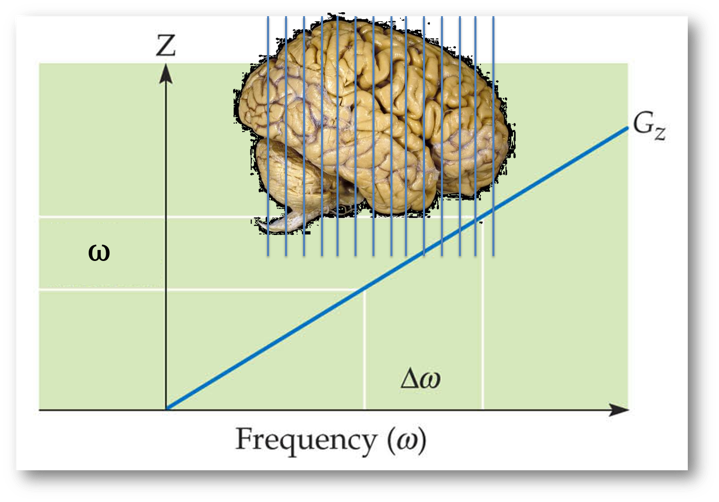

The idea is this. We introduce a magnetic field gradient across the sample changing the Larmor frequency across the sample. When we deliver an RF pulse at a particular frequency, then, only the spins in one portion of the gradient field will be excited.

What would such a pulse look like? Let's create some examples.

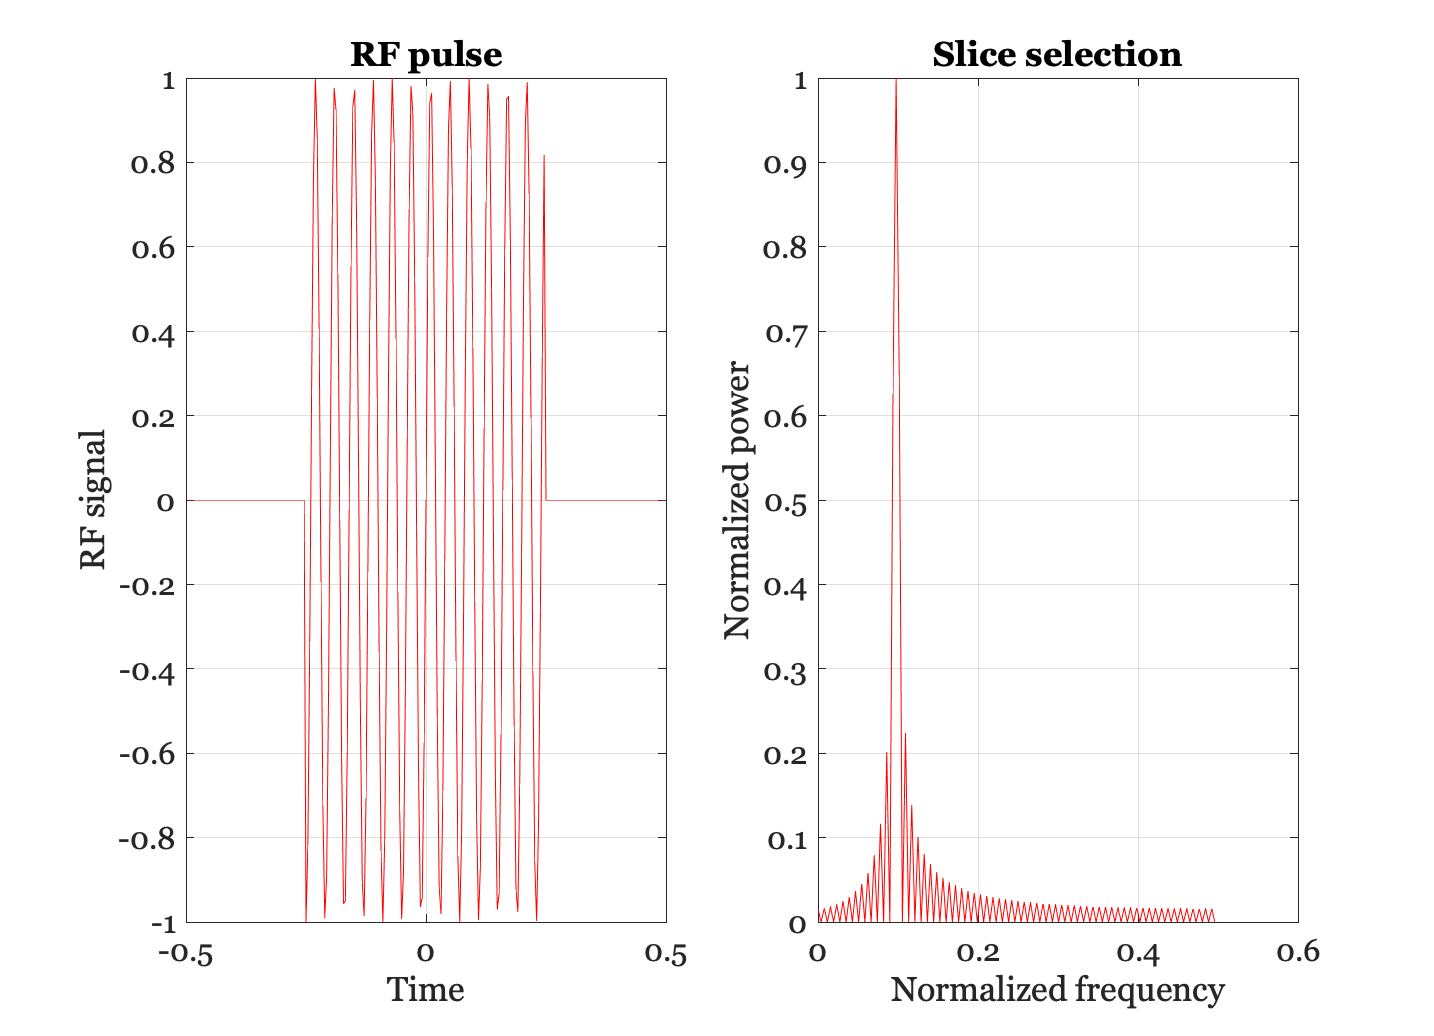

% We initialize the rfPulse to
% zero, and then we initialize some parameters.
nTime = 256;  t = (1:nTime)/nTime - 0.5;
rfPulse = zeros(1,nTime); 
pulseDuration = round(nTime/2);
pulseStart = nTime/2 - pulseDuration/2;
pulseStop = pulseStart + pulseDuration-1;
pulseT = t((pulseStart:pulseStop));

% We choose a pulse frequency.  This frequency will excite the planar
% section of the tissue that is at the Larmor frequency we wish to excite.
pulseFreq = 25;

% Now, create a sinusoid RF pulse at that frequency.
rfPulse(pulseStart:pulseStop) = sin(2*pi*pulseFreq*pulseT);
figure(1); clf;
subplot(1,2,1), plot(t,rfPulse); xlabel('Time'); ylabel('RF signal'); 
title('RF pulse'); grid on

% Here is the Fourier Transform spectrum of the RF pulse.
% The frequency content of the pulse determines which plane we excite.
subplot(1,2,2), 
[s,f] = powerSpecDens(rfPulse);
plot(f,s); grid on;
xlabel('Normalized frequency'); ylabel('Normalized power'); 
title('Slice selection')

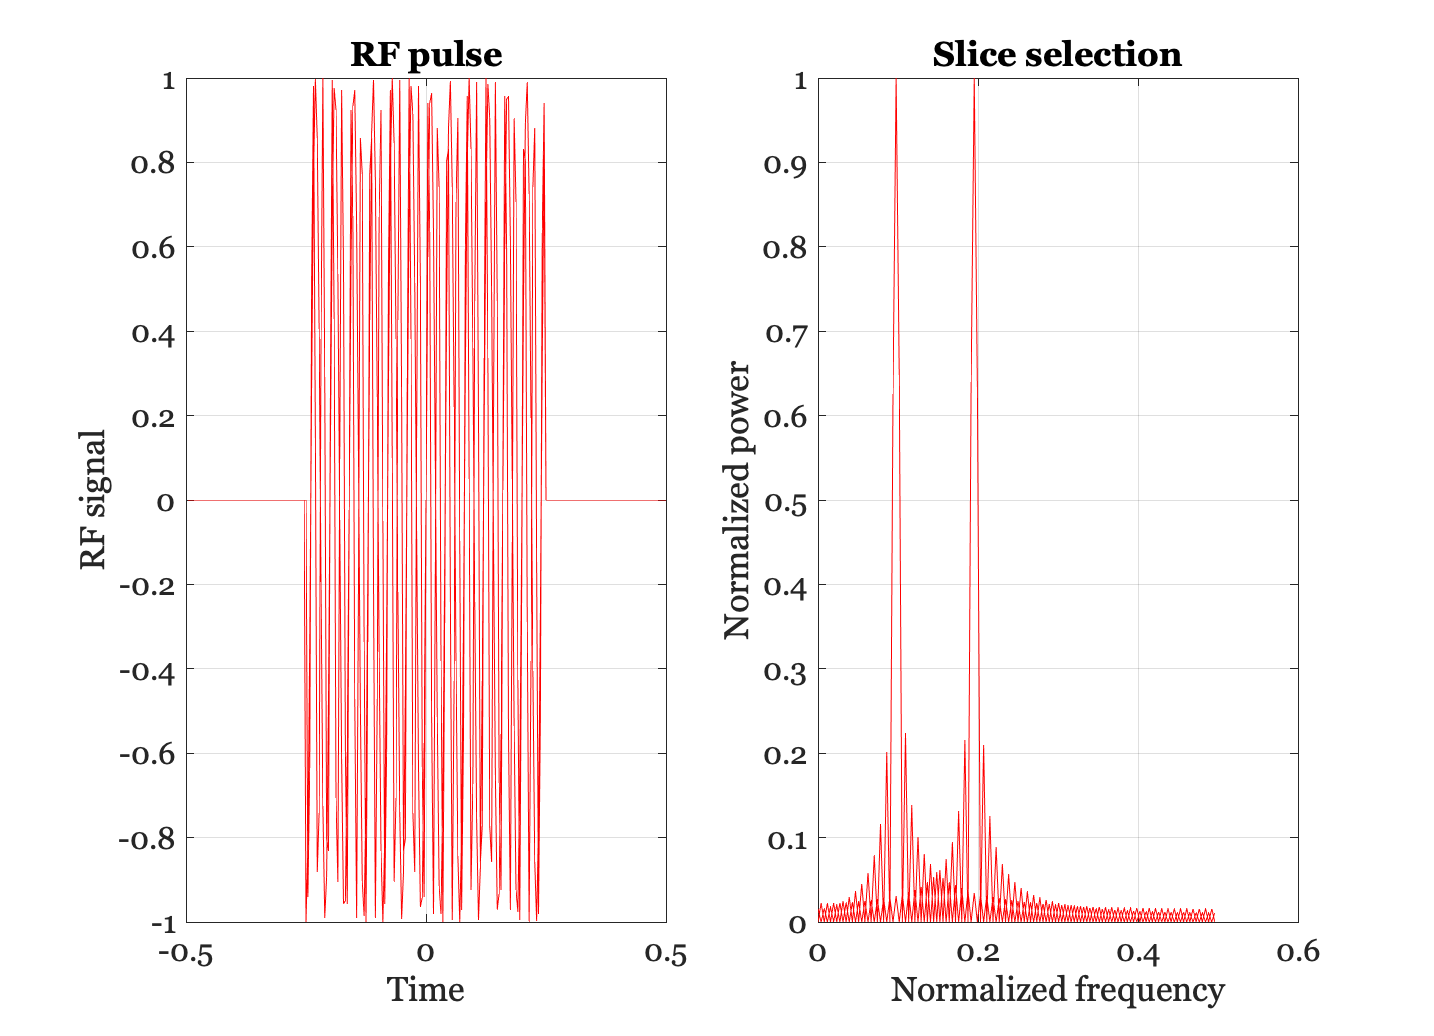

% We can control the position that is excited by adjusting the frequency.
pulseFreq = 50;
rfPulse(pulseStart:pulseStop) = sin(2*pi*pulseFreq*pulseT);
subplot(1,2,1), hold on, plot(t,rfPulse, 'r'); 
xlabel('Time'); ylabel('RF signal'); title('RF pulse')
subplot(1,2,2), hold on
[s,f] = powerSpecDens(rfPulse);
plot(f,s, 'r'); grid on;
xlabel('Normalized frequency'); ylabel('Normalized power'); 
title('Slice selection')

## Slice width

A second parameter we would like to control is the slice width.   There are two ways we can adjust the slice width.  One way, as described in the book, is to change the gradient.  A second way, illustrated here, is to change the timing of the RF pulse.

In this example, we create an RF pulse that is the product of the sinusoid and a sinc function.  (Type help sinc to read about this important function). Each sinc function has its own frequency, too. 

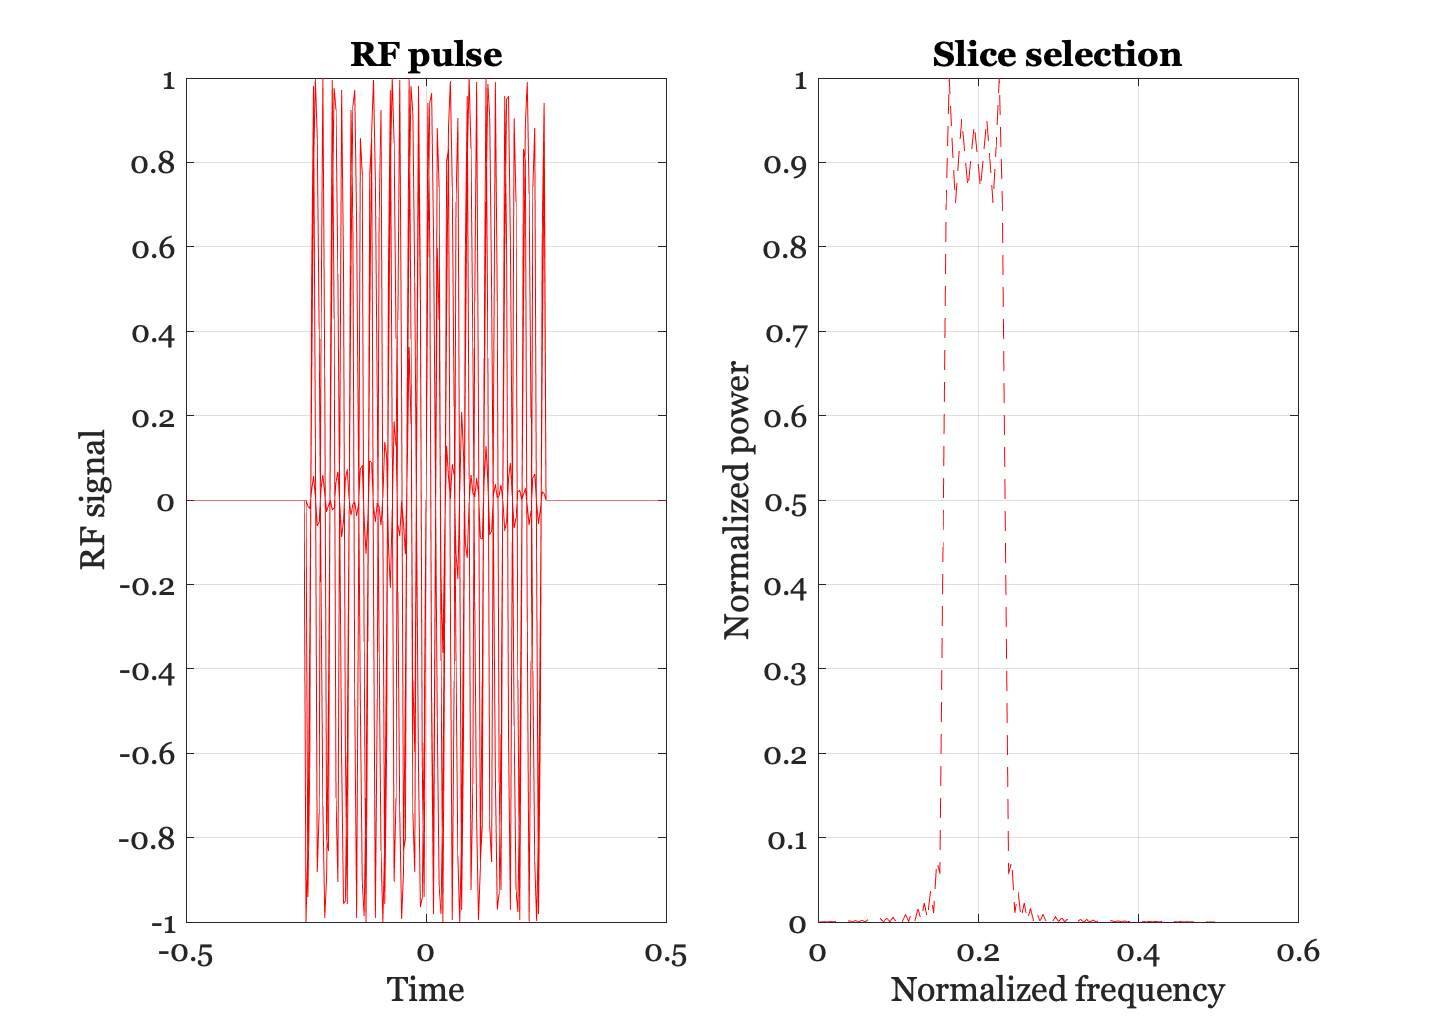

sincFreq  = 20;      % Try 10, 20 and 40.
pulseFreq = 50;      % Try 25, 50 and 75.

rfPulse(pulseStart:pulseStop) = sin(2*pi*pulseFreq*pulseT);
rfPulse(pulseStart:pulseStop) = ...
    rfPulse(pulseStart:pulseStop).*sincFunction(sincFreq*pulseT);

hold off;
subplot(1,2,1), plot(t,rfPulse,'r-'); 
xlabel('Time'); ylabel('RF signal'); title('RF pulse')

hold off;
subplot(1,2,2), [s,f] = powerSpecDens(rfPulse); plot(f,s,'r--'); grid on; 
xlabel('Normalized frequency'); ylabel('Normalized power'); 
title('Slice selection')

## Question 4

Run the above code a few times, varying the pulse and sinc frequency  values.  What effect does each parameter have on slice position and slice width?

## Frequency encoding and phase encoding together

The Hornak MRI book, [http://www.cis.rit.edu/htbooks/mri/](http://www.cis.rit.edu/htbooks/mri/), has a very good discussion of imaging, including frequency and phase encoding. Please read Chapters 6 and 7 for a useful discussion of the principles further described here. Also, the Huettel et al. book is very clear and useful in describing pulse sequences (Chapters 4 and 5).

Earlier, we reviewed how to use a gradient field to associate different positions along a line with different RF signal frequencies. That method is often called frequency encoding. In this section, we describe how to measure along the second spatial dimension. This measurement is sometimes called the phase-encoding dimension. Taken together, the methods described in this section are sometimes called Fourier Transform imaging.

Consider the problem of identifying signals from 4 beakers placed at the corners of a square. These four beakers are in the planar section and the spins were set in motion using the methods described in the previous section. 

First, we set up the basic parameters for the four beakers.

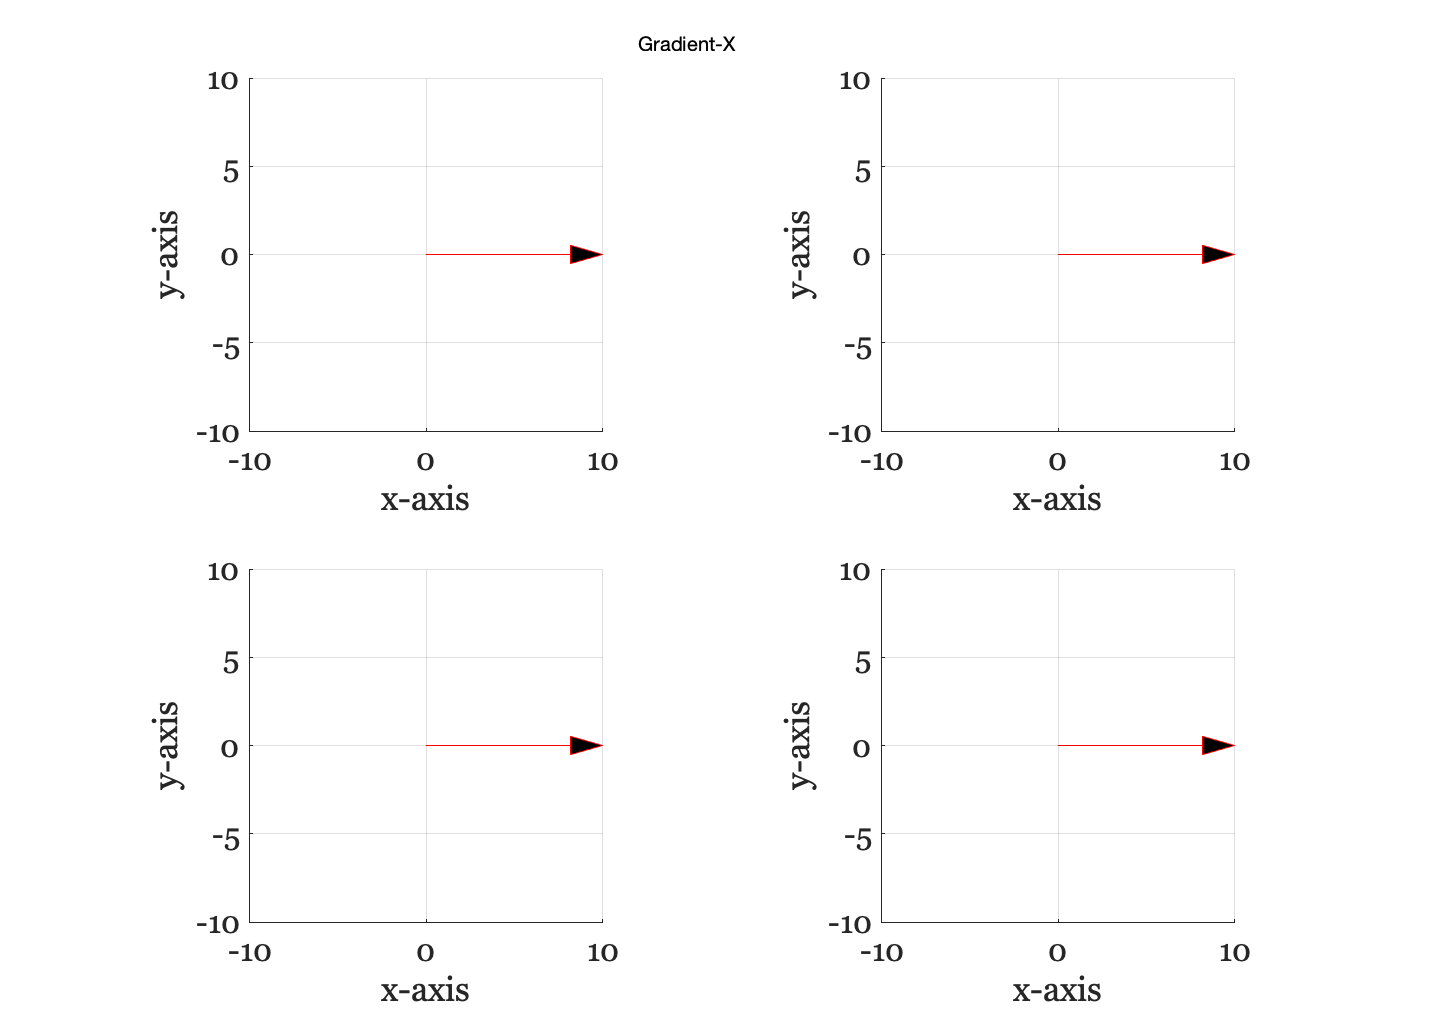

clear T1; clear larmorFreq; clear ph; clear signal;
T1 = [1,2;3,4]/2; larmorFreq = [15, 50]; 
ph = [0, pi]; t = (0:.02:5); 
Mo = 1;

rate = [0,0,0,0];
spinDir = [10,0; 10,0; 10,0; 10,0];
figure(1), clf
phaseEncode(rate,spinDir,1,'Gradient-X');

### Apply a gradient across the x-axis (Gx)

In the presence of this gradient, the signals from the two beakers on the left will differ from  the RF signals emitted by the two beakers on the right. When we measure with only the x-gradient (Gx), we obtain the sum of the two beakers on the left in one frequency band and the sum of the two beakers on the right in a second frequency band.

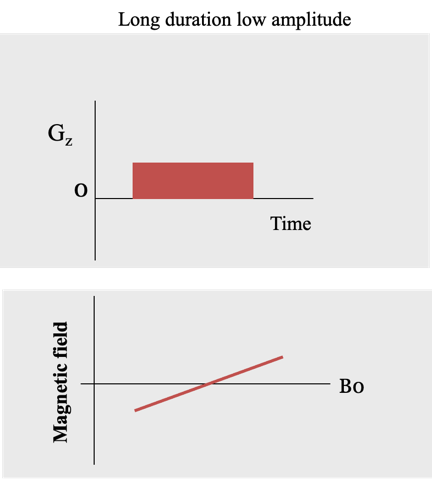

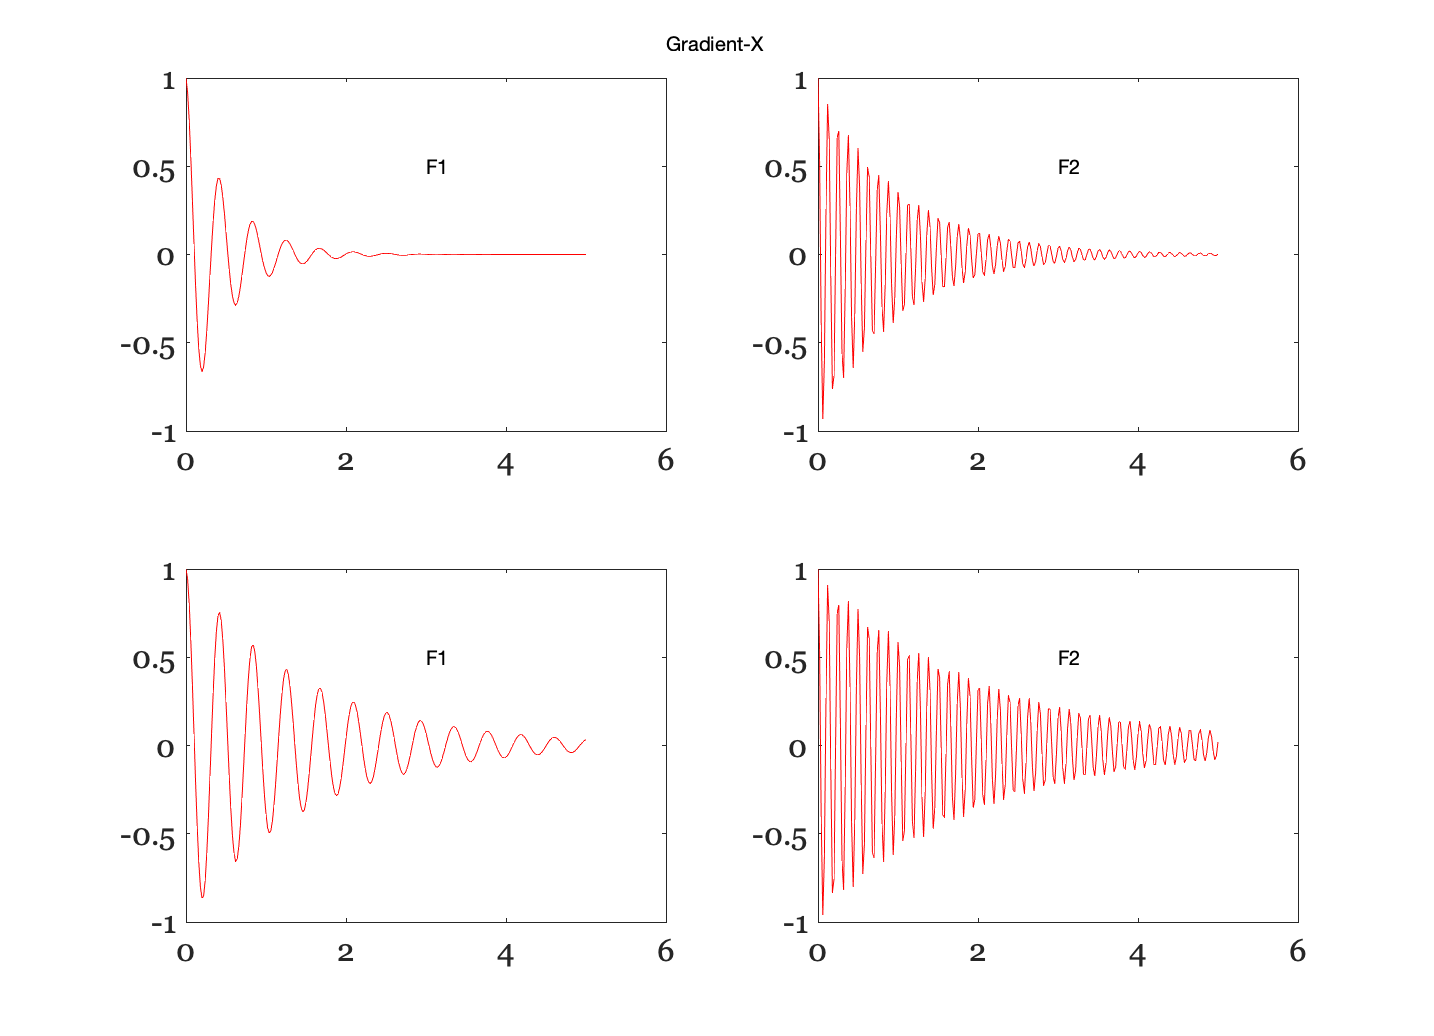

f = [larmorFreq(1),larmorFreq(1),larmorFreq(2), larmorFreq(2)];
p = [ph(1),ph(1),ph(1),ph(1)];
figure(1), clf; 
signal = plotRF(f,p,t,T1,Mo,'Gradient-X');

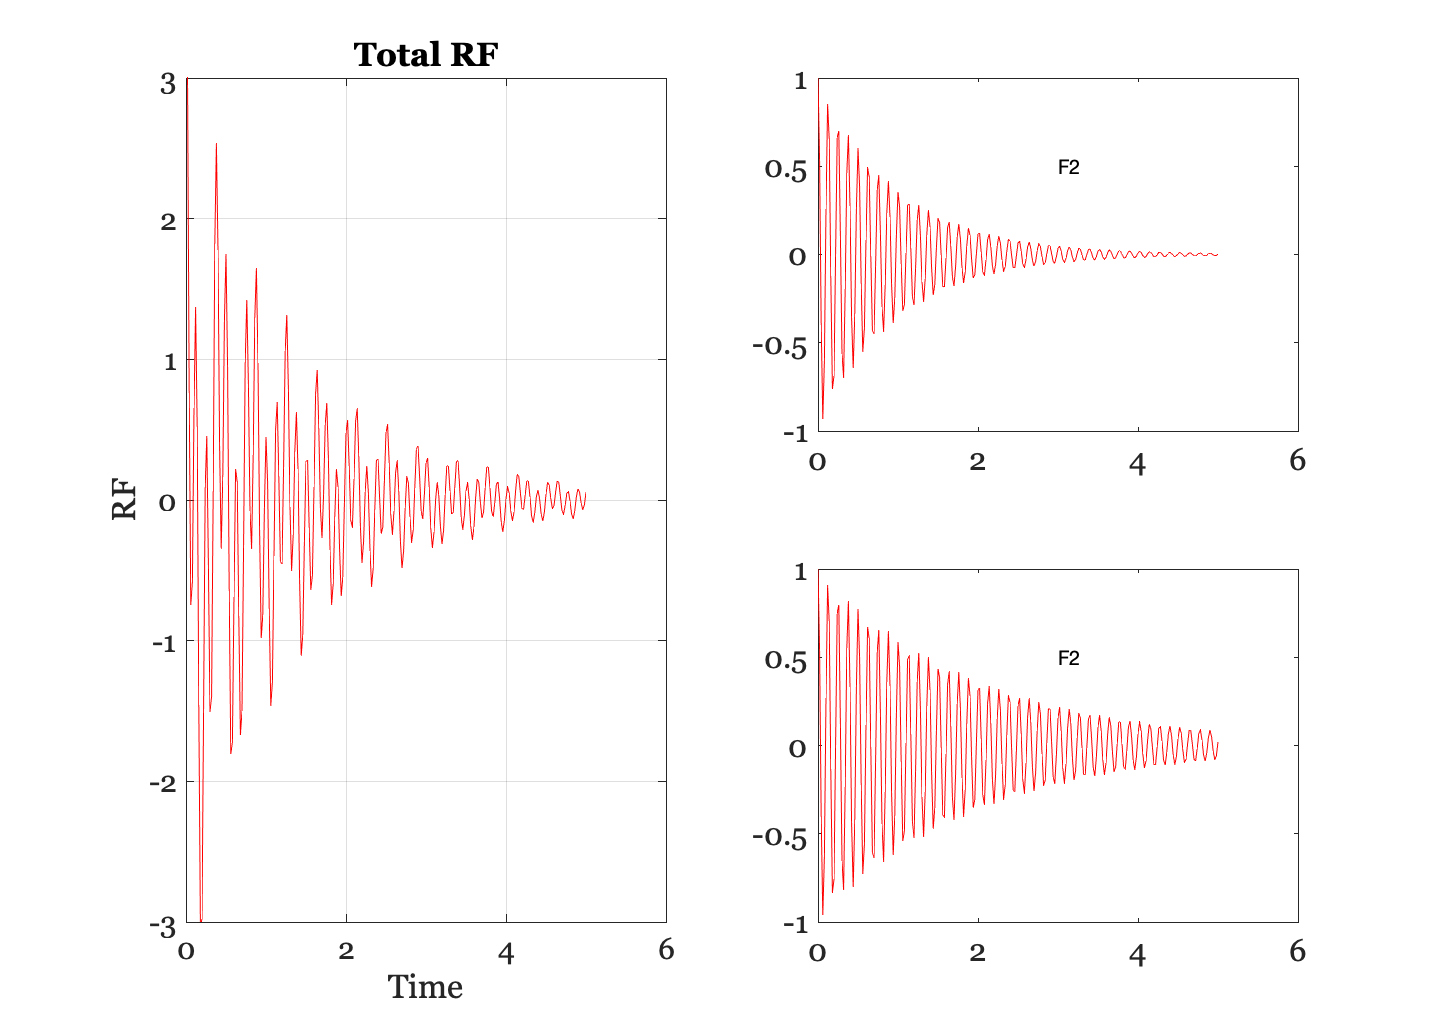


% Total signal
subplot(1,2,1)
s = sum(squeeze(sum(signal,1)),1);
plot(t,s);xlabel('Time'); ylabel('RF'); title('Total RF'); grid on
set(gca,'ylim',[-3 3]);

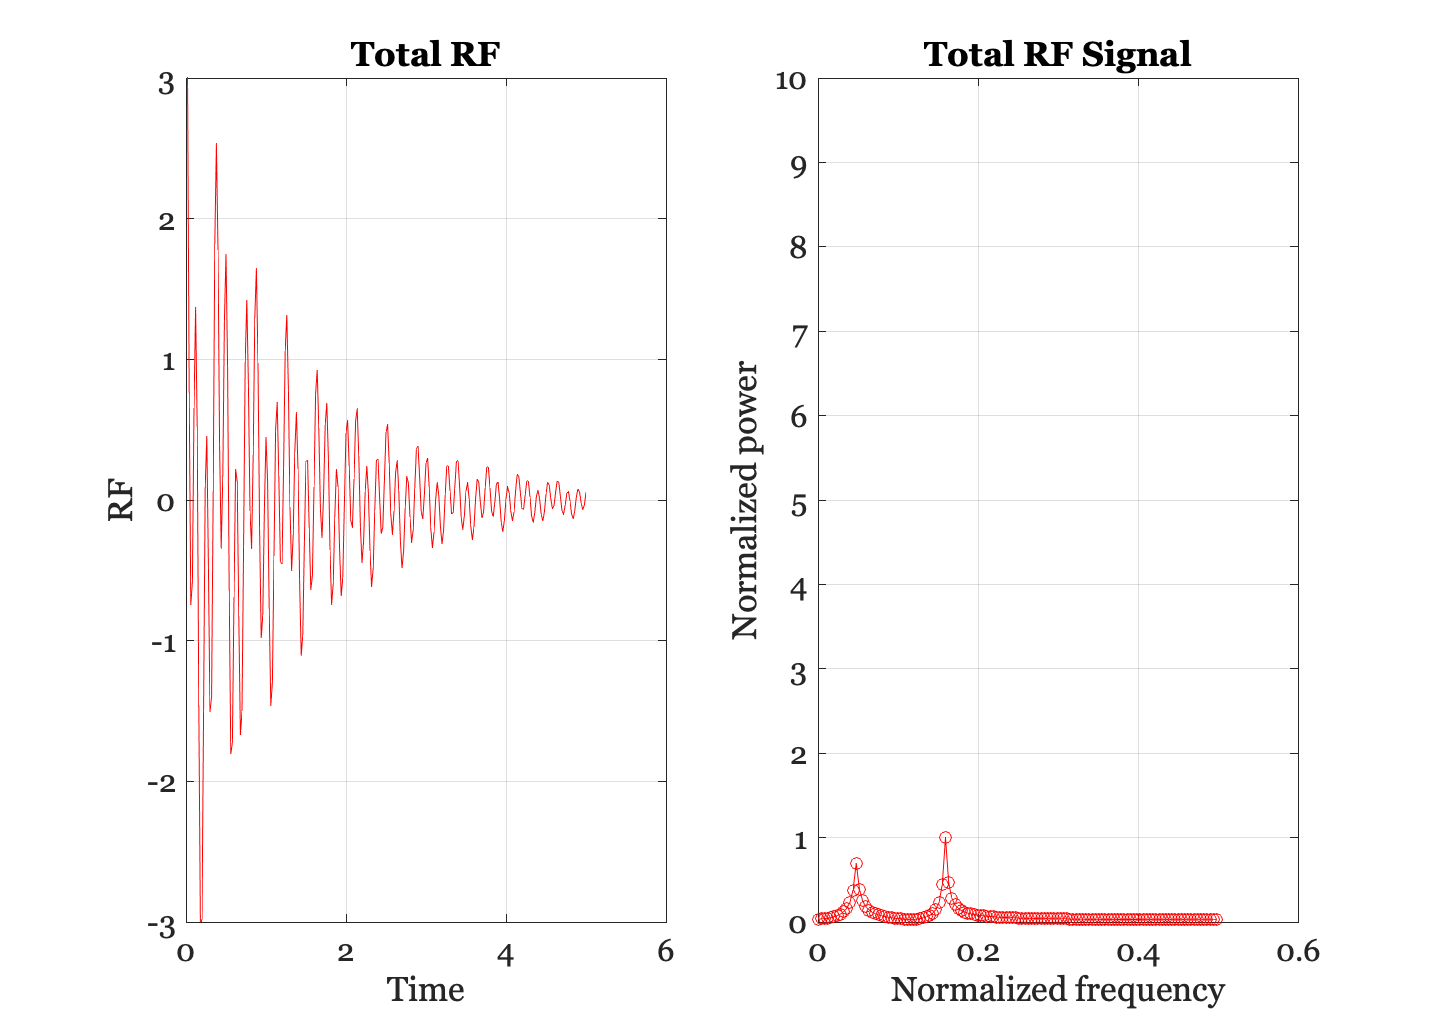

subplot(1,2,2)
[p,f] = powerSpecDens(s); 
plot(f,p,'o-'); grid on; set(gca,'ylim',[0,10]);
xlabel('Normalized frequency'); ylabel('Normalized power'); 
title('Total RF Signal')

### We turn off  Gx  and introduce a gradient in the y-dimension (Gy).  

This changes the Larmor frequency of the beakers at the top and bottom of the square.  Suppose the frequency for the bottom beakers is a little lower. Then the spins in the bottom beakers rotate more slowly and they end up pointing in a different direction from the spins at the top.  After applying Gy for a certain amount of time, the spins at the top and bottom will point in opposite directions.

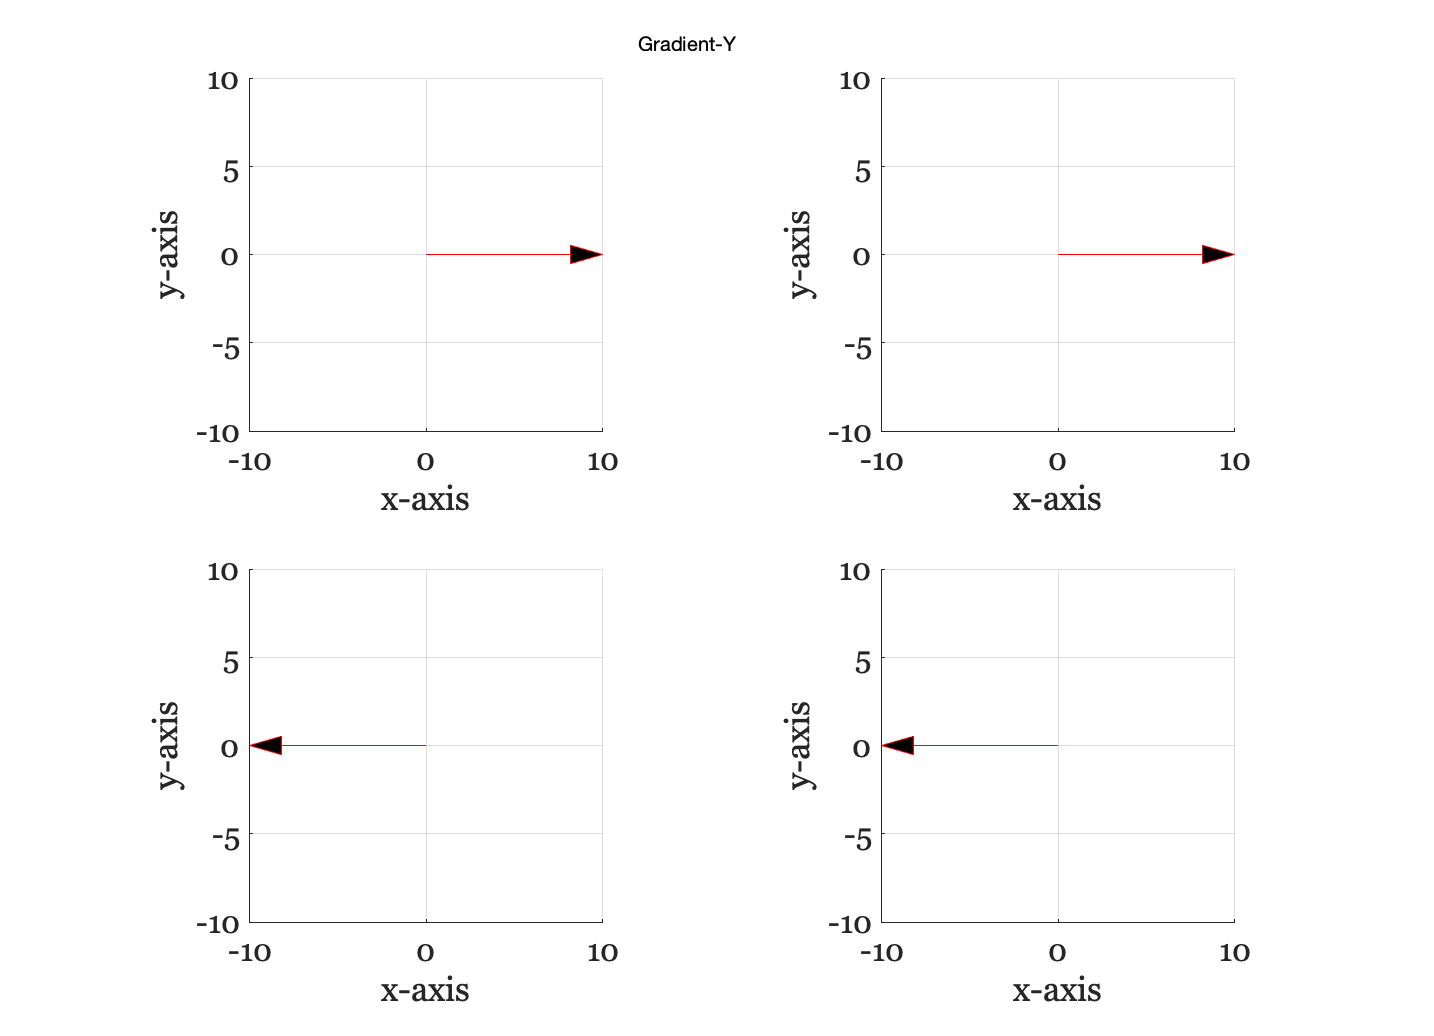

rate = [pi/8 pi/8 pi/16 pi/16];
spinDir = [10,0; 10,0; 10,0; 10,0];
figure(1), clf
phaseEncode(rate,spinDir,15,'Gradient-Y');

### Next, we switch off  Gy and turn on Gx.  

As before we will measure the combination of the spins on the left at one frequency and the combination of the spins at the right at a different frequency.  Because the spins of the top and bottom beaker oppose one another, however, the total RF signal we obtain now is the difference between the top and bottom.  

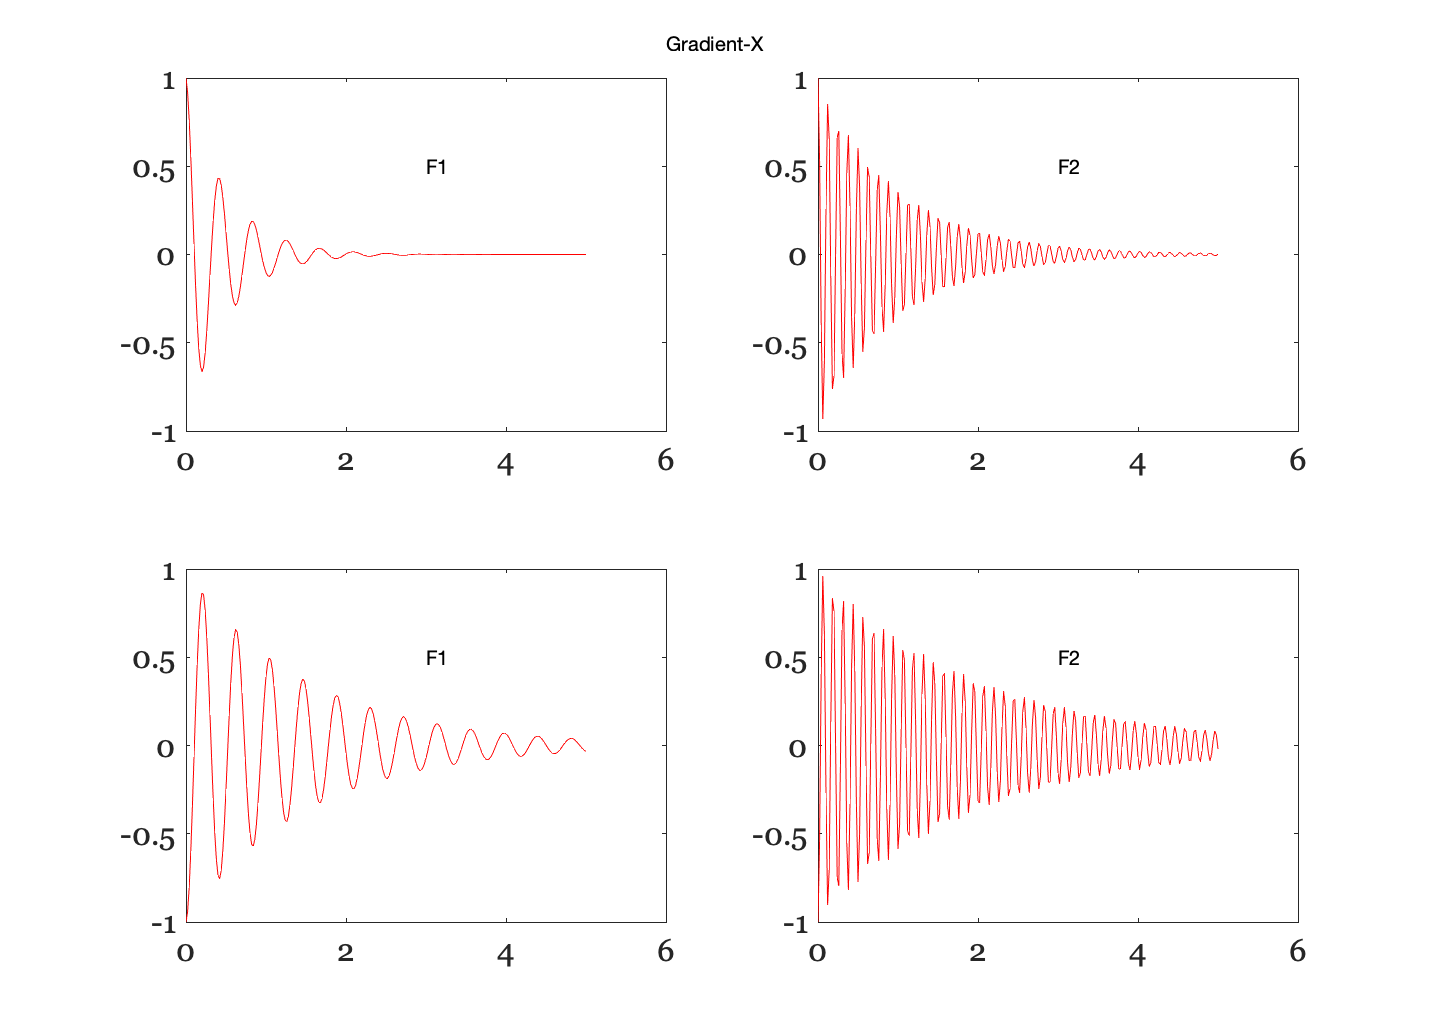

f = [larmorFreq(1),larmorFreq(1),larmorFreq(2),larmorFreq(2)];
p = [ph(1),ph(2),ph(1),ph(2)];
figure(1), clf; signal = plotRF(f,p,t,T1,Mo,'Gradient-X');

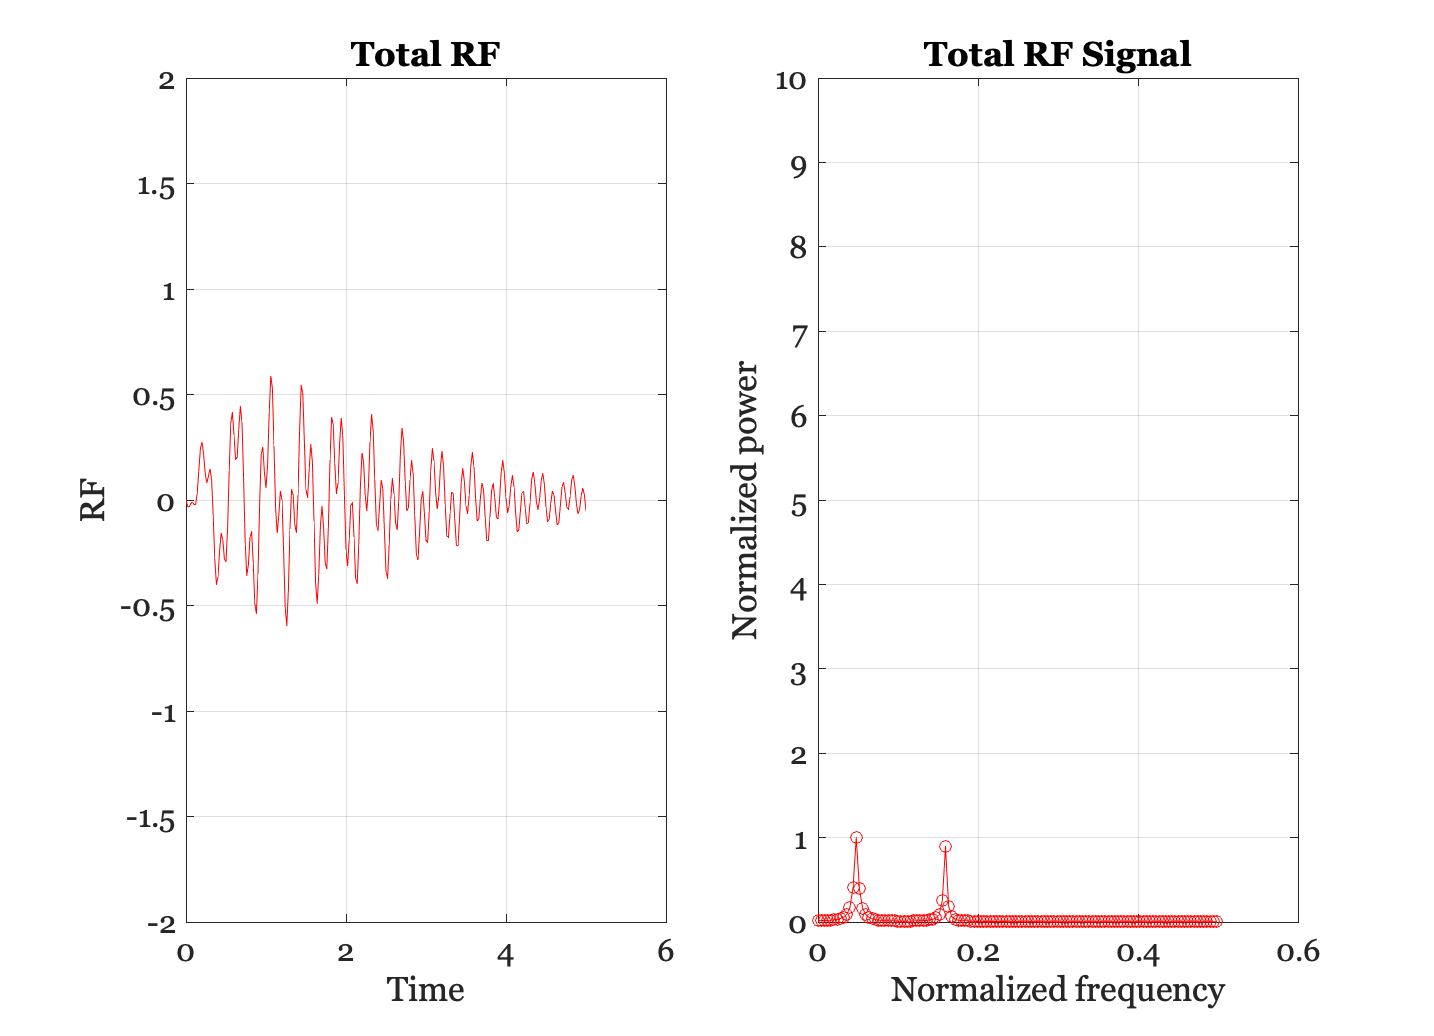


% Total signal
clf; subplot(1,2,1)
s = sum(squeeze(sum(signal,1)),1);
plot(t,s); xlabel('Time'); ylabel('RF'); title('Total RF'); grid on
set(gca,'ylim',[-2 2]);
subplot(1,2,2)
[p,f] = powerSpecDens(s); 
plot(f,p,'o-'); grid on; set(gca,'ylim',[0,10]);
xlabel('Normalized frequency'); ylabel('Normalized power'); 
title('Total RF Signal')

These two measurements at the main frequencies provide an estimate of the sum and the difference of the time constants in the upper and lower beakers. Specifically, the two measurements are


$$$m_1 = a + b$$$



$$m_2 = a - b$$


Measuring $m_1$ and $m_2$ we can solve for a and b.


$$\begin{array}{l}
m_{1\;} +m_2 =2a\\
m_{1\;} -m_2 =2b
\end{array}$$


In this example, the frequency of the RF signal codes the x-dimension.  This dimension is called the frequency dimension.  We keep adjusting the  phase of the spins along the y-dimension. Hence, this dimension is called the phase-encode dimension.  People keep track of these two dimensions because the phase-encode direction is subject to more measurement error than the frequency encode direction.